optoChan_0Ind = 133;
facemotionThresh = 1000;
layerBorders = [0 100; 101 300; 301 450; 451 650; 651 900; 1100 inf];
serverPath = 'G:\ChR2_dual_summer_2023';

## Animal 6560

Day 4 - Session A

basepath = [serverPath '\6560\JR_23_08_17_ChR2_dual_animal_6560_session_A\JR_23_08_17_ChR2_dual_animal_6560_session_A_230817_112238'];

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


% lfpReref = lfp;
% lfpReref.data = lfp.data - median(lfp.data,2);

lfpContra = bz_GetLFP(64:127, 'basepath', basepath);

Loading Channels 64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

wspecs = calcWaveletSpectrograms(lfp, [], basepath);

Loading wavespec data...
Loading wavespec data (reref)...


power = NaN

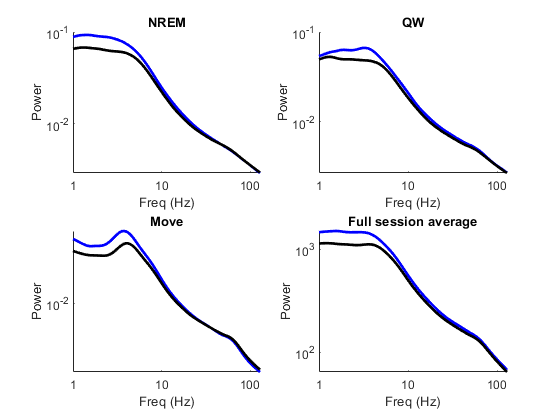

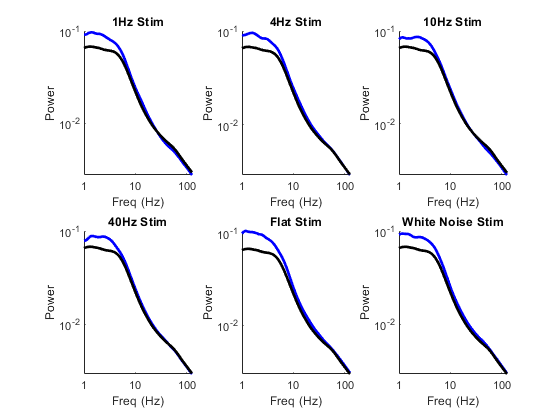

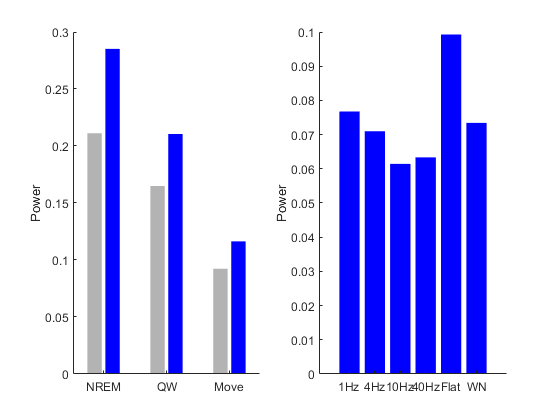

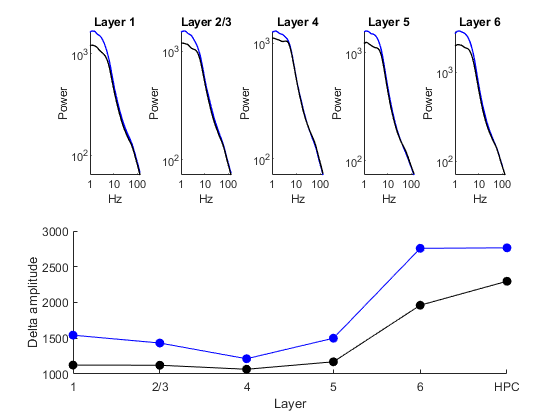

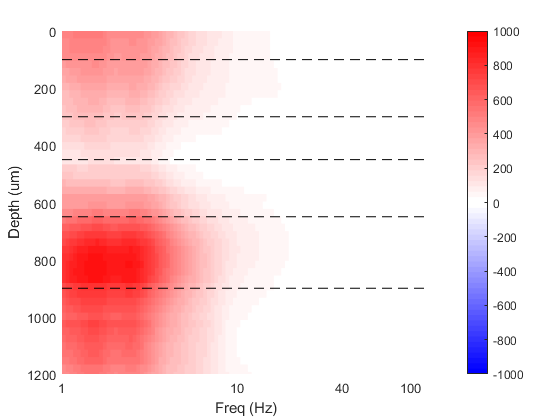

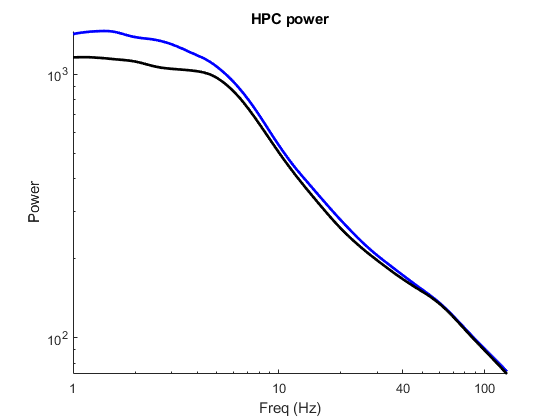

Animal6560a = struct with fields:
    ipsi: [1×1 struct]



Animal6560a.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


freqs = wspecs.reref.ipsi.freqs;
deltamask = wspecs.reref.ipsi.freqs <= 4;
deltafreqs = wspecs.reref.ipsi.freqs(deltamask);
clearvars wspecs lfp lfpContra

Day 2 - Session A

basepath = [serverPath '\6560\JR_23_08_15_ChR2_dual_animal_6560_session_A\JR_23_08_15_ChR2_dual_animal_6560_session_A_230815_100405'];

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


% lfpReref = lfp;
% lfpReref.data = lfp.data - median(lfp.data,2);

lfpContra = bz_GetLFP(64:127, 'basepath', basepath);

Loading Channels 64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

wspecs = calcWaveletSpectrograms(lfp, [], basepath);

Loading wavespec data...
Loading wavespec data (reref)...


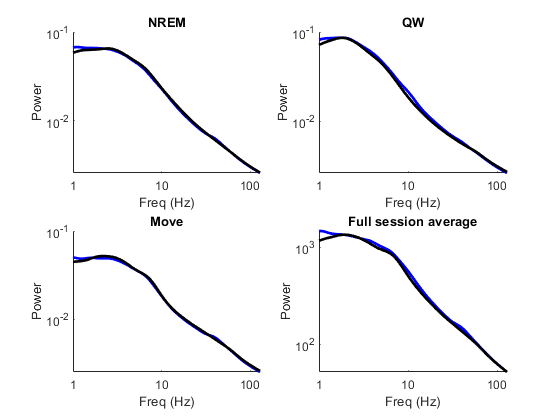

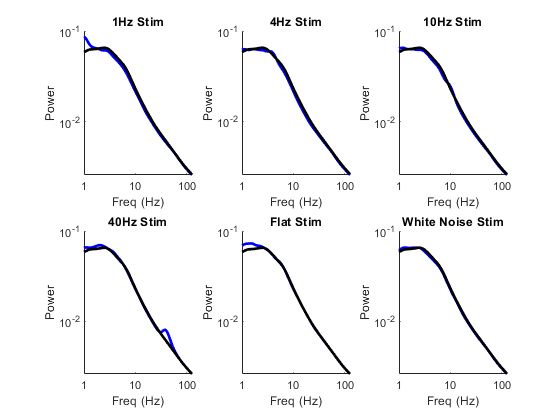

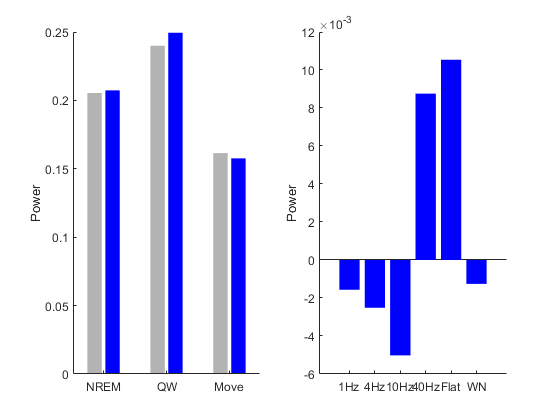

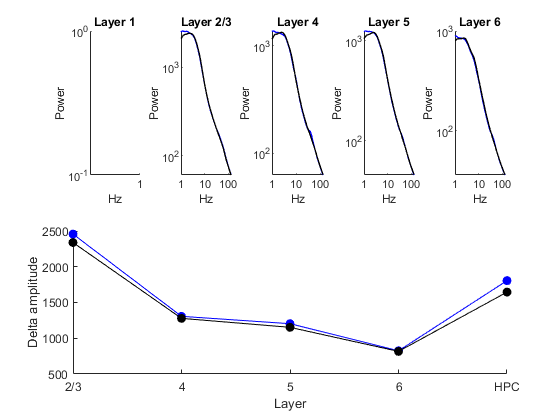

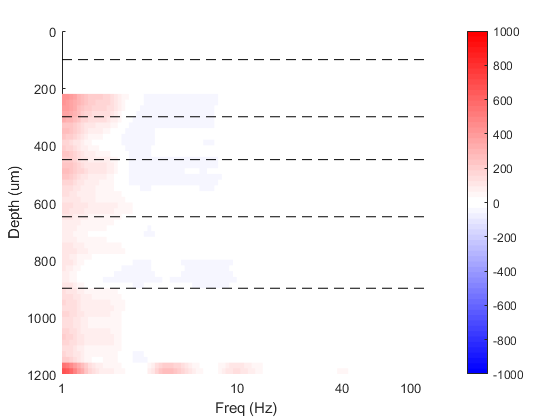

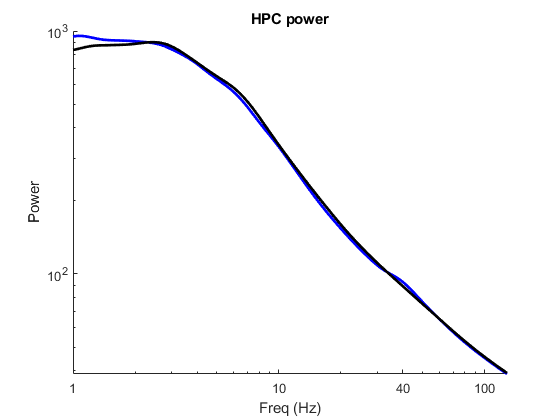

Animal6560b = struct with fields:
    ipsi: [1×1 struct]



Animal6560b.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp lfpContra

Day 3 - Session C

-- not used, flat LFPs, no spikes

% basepath = 'E:\ChR2_dual_summer_2023\6560\JR_23_08_16_ChR2_dual_animal_6560_session_C\JR_23_08_16_ChR2_dual_animal_6560_session_C_230816_102629';
%
% lfp = bz_GetLFP(0:63, 'basepath',basepath);
% % lfpReref = lfp;
% % lfpReref.data = lfp.data - median(lfp.data,2);
%
% lfpContra = bz_GetLFP(64:127, 'basepath', basepath);
%
% chanDepth_um = layerLocalization(basepath);
% co = getChannelOrder2('H3');
% 
% sess = bz_getSessionInfo(basepath);
% hpcChans = strcmp(sess.region(1:64), 'HPC');
%
% % Get details of optogenetic stimulation
% optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);
% optoInts = getOptoInts(basepath, optostim, facemotionThresh);
%
% wspecs = calcWaveletSpectrograms(lfp, [], basepath);
%
% % Animal6560.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)
%
% clearvars wspecs lfp lfpContra

## Animal 6556

Day 2 - Session A

basepath = [serverPath '\6556\JR_23_08_22_ChR2_dual_animal_6556_session_A\JR_23_08_22_ChR2_dual_animal_6556_session_A_230822_100542'];

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


% lfpReref = lfp;
% lfpReref.data = lfp.data - median(lfp.data,2);

lfpContra = bz_GetLFP(64:127, 'basepath', basepath);

Loading Channels 64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

wspecs = calcWaveletSpectrograms(lfp, [], basepath);

Loading wavespec data...
Loading wavespec data (reref)...


power = NaN

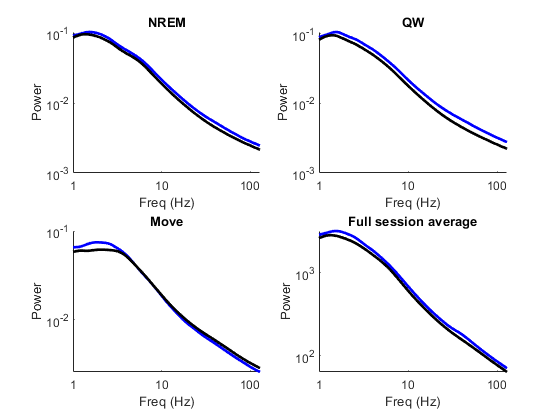

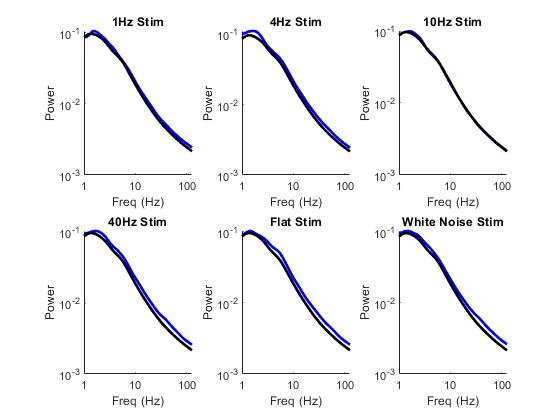

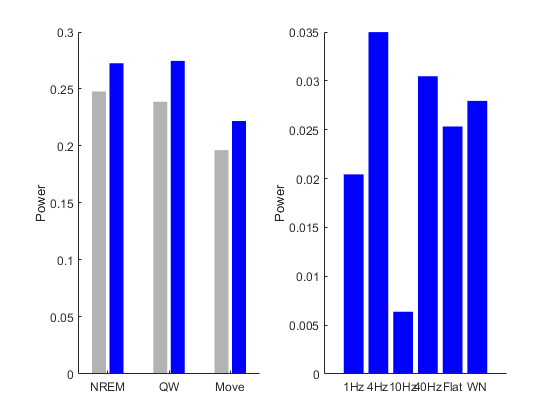

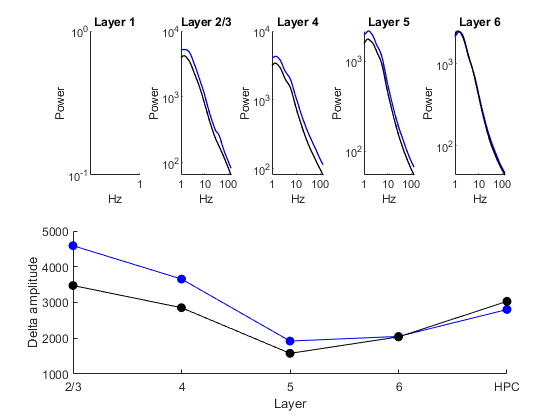

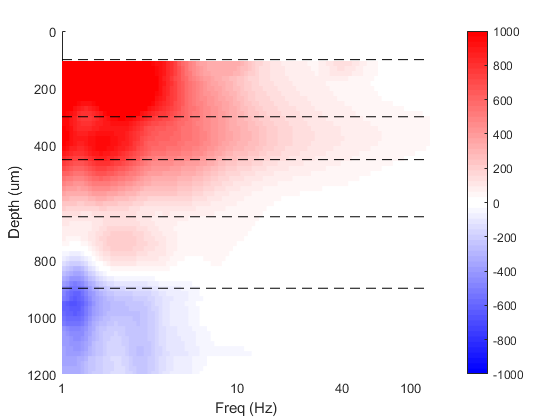

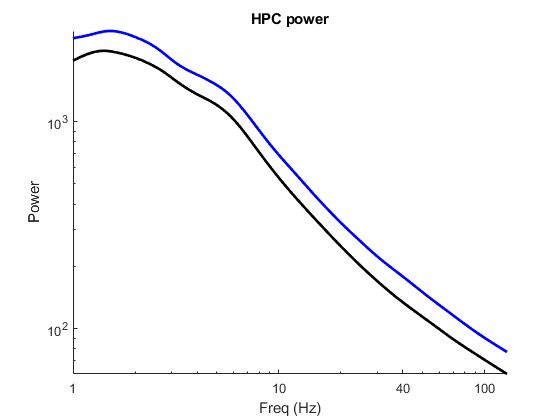

Animal6556a = struct with fields:
    ipsi: [1×1 struct]



Animal6556a.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp lfpContra

Day 2 - Session C

basepath = [serverPath '\6556\JR_23_08_23_ChR2_dual_animal_6556_session_C\JR_23_08_23_ChR2_dual_animal_6556_session_C_230823_100827'];

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


% lfpReref = lfp;
% lfpReref.data = lfp.data - median(lfp.data,2);

lfpContra = bz_GetLFP(64:127, 'basepath', basepath);

Loading Channels 64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

wspecs = calcWaveletSpectrograms(lfp, [], basepath);

Loading wavespec data...
Loading wavespec data (reref)...


power = NaN

power = NaN

power = NaN

power = NaN

power = NaN

power = NaN

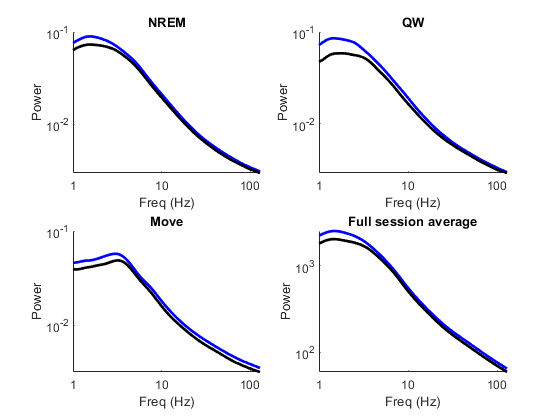

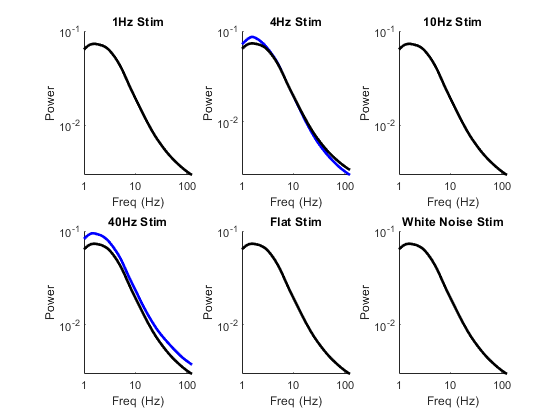

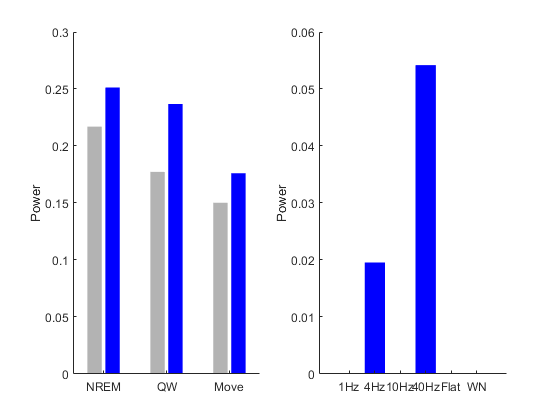

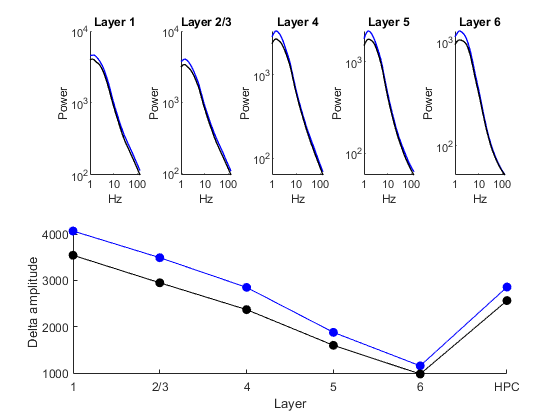

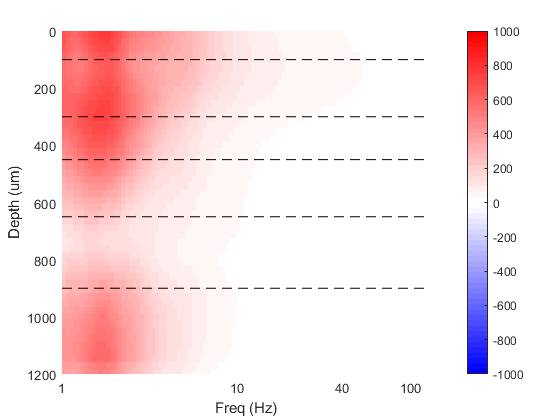

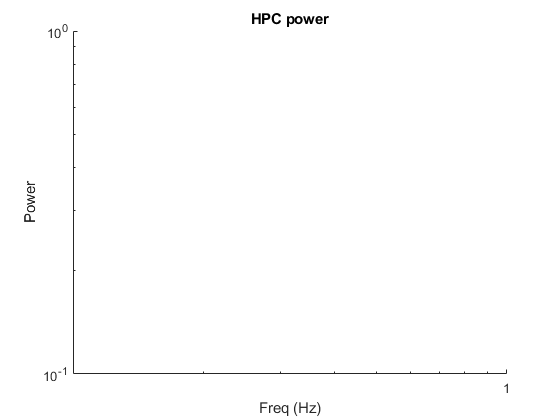

Animal6556b = struct with fields:
    ipsi: [1×1 struct]


Animal6556b.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)

clearvars wspecs lfp lfpContra

Day 4 - Session A

basepath = [serverPath '\6556\JR_23_08_24_ChR2_dual_animal_6556_session_A\JR_23_08_24_ChR2_dual_animal_6556_session_A_230824_105116'];

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


% lfpReref = lfp;
% lfpReref.data = lfp.data - median(lfp.data,2);

lfpContra = bz_GetLFP(64:127, 'basepath', basepath);

Loading Channels 64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

wspecs = calcWaveletSpectrograms(lfp, [], basepath);

Loading wavespec data...
Loading wavespec data (reref)...


power = NaN

power = NaN

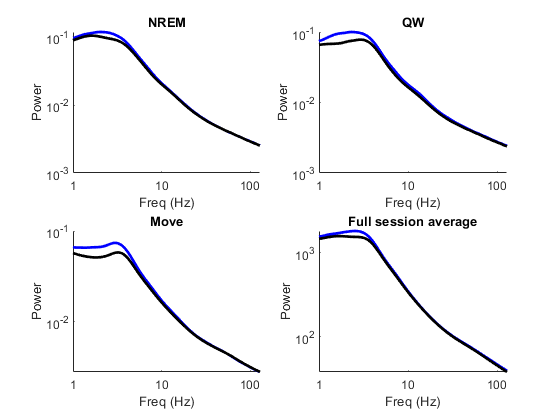

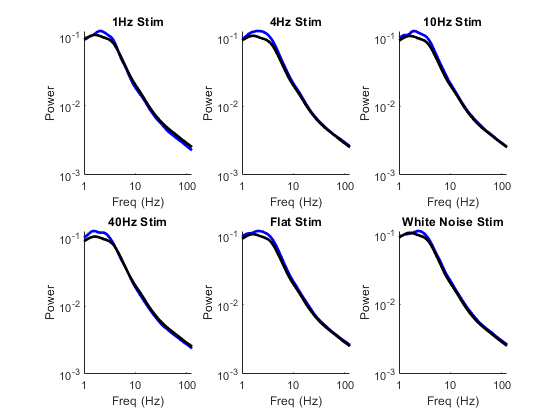

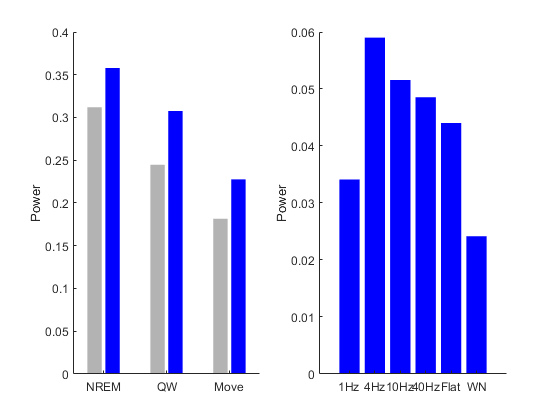

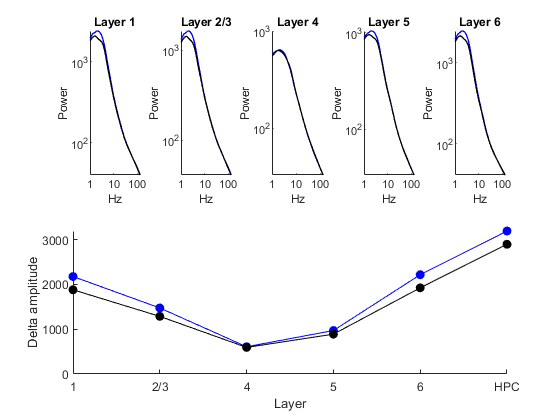

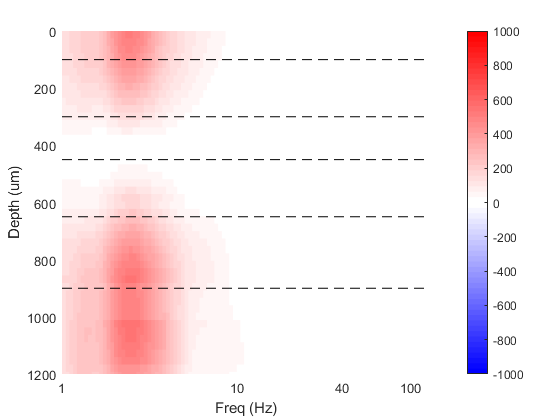

Animal6556c = struct with fields:
    ipsi: [1×1 struct]



Animal6556c.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp lfpContra

Day 5 - Session C

basepath = [serverPath '\6556\JR_23_08_25_ChR2_dual_animal_6556_session_C\JR_23_08_25_ChR2_dual_animal_6556_session_C_230825_104818'];

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


% lfpReref = lfp;
% lfpReref.data = lfp.data - median(lfp.data,2);

lfpContra = bz_GetLFP(64:127, 'basepath', basepath);

Loading Channels 64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

wspecs = calcWaveletSpectrograms(lfp, [], basepath);

Loading wavespec data...
Loading wavespec data (reref)...


power = NaN

power = NaN

power = NaN

power = NaN

power = NaN

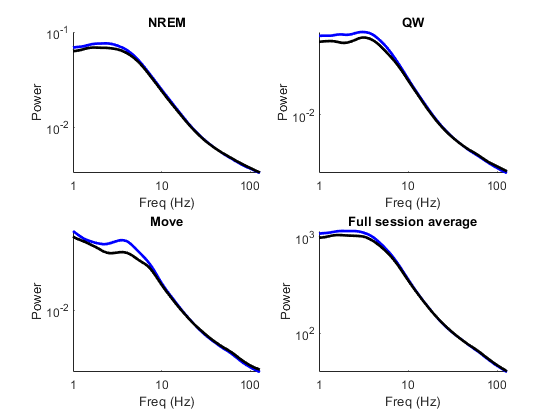

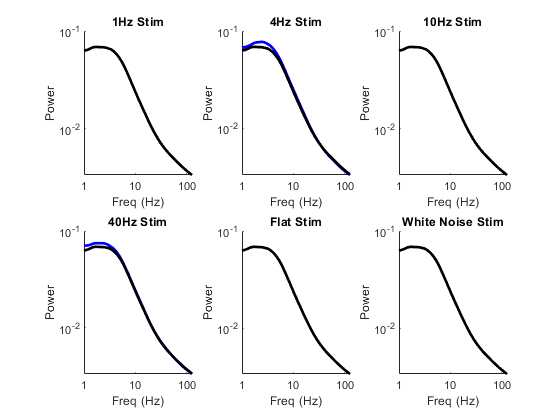

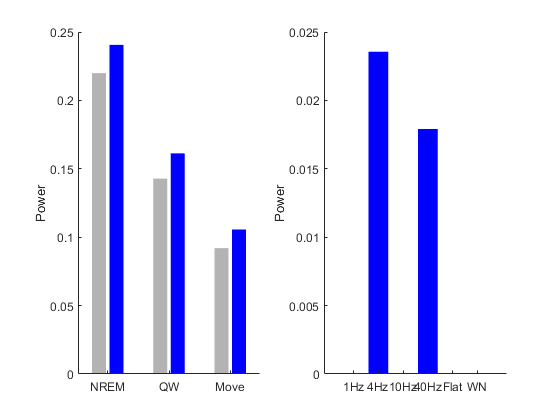

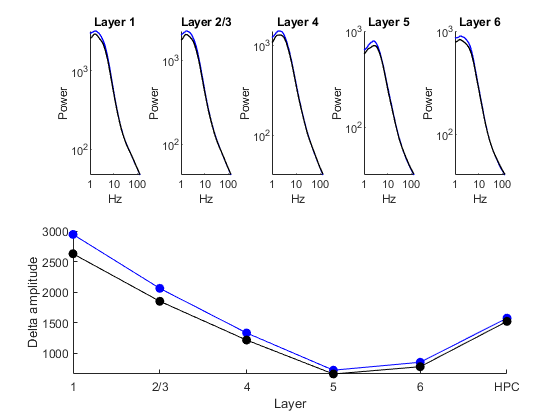

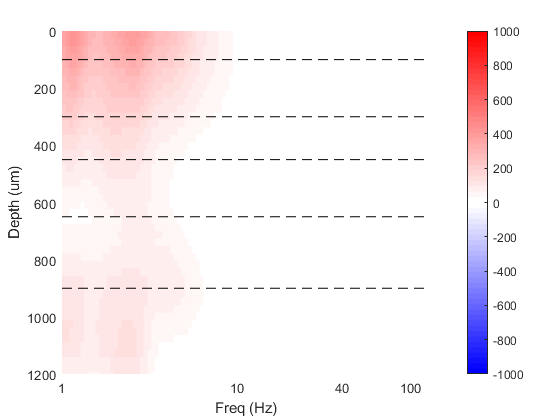

Animal6556d = struct with fields:
    ipsi: [1×1 struct]



Animal6556d.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp lfpContra

## Animal 7149

Day 2 - Session A

basepath = [serverPath '\7149\JR_23_09_06_ChR2_dual_animal_7149_session_A\JR_23_09_06_ChR2_dual_animal_7149_session_A_230906_103733'];

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


% lfpReref = lfp;
% lfpReref.data = lfp.data - median(lfp.data,2);

lfpContra = bz_GetLFP(64:127, 'basepath', basepath);

Loading Channels 64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

wspecs = calcWaveletSpectrograms(lfp, [], basepath);

Loading wavespec data...
Loading wavespec data (reref)...


power = NaN

power = NaN

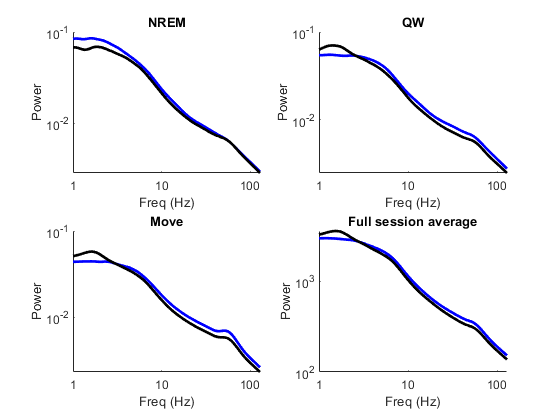

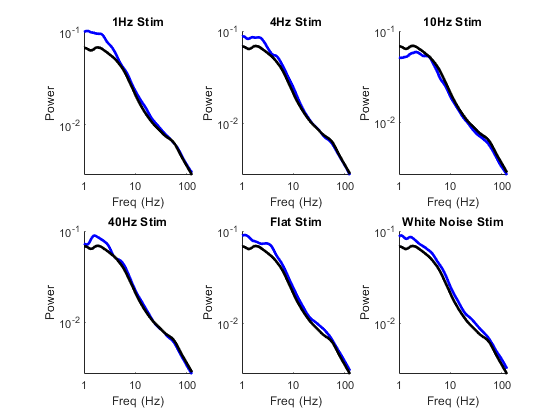

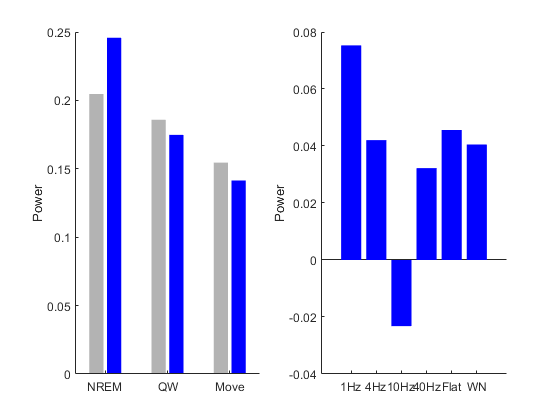

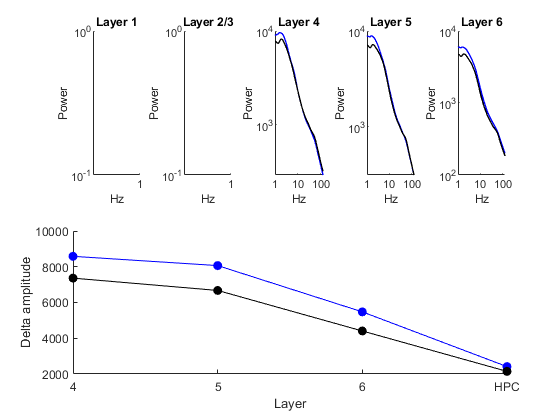

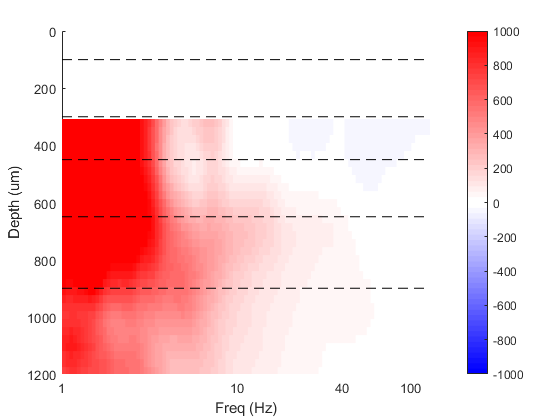

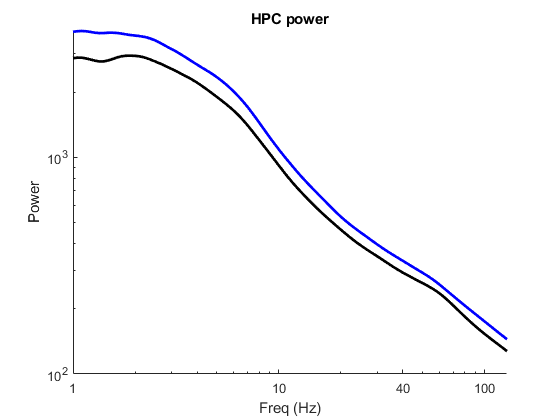

Animal7149a = struct with fields:
    ipsi: [1×1 struct]



Animal7149a.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp lfpContra

Day 3 - Session C

basepath = [serverPath '\7149\JR_23_09_07_ChR2_dual_animal_7149_session_C\JR_23_09_07_ChR2_dual_animal_7149_session_C_230907_100125'];

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


% lfpReref = lfp;
% lfpReref.data = lfp.data - median(lfp.data,2);

lfpContra = bz_GetLFP(64:127, 'basepath', basepath);

Loading Channels 64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

wspecs = calcWaveletSpectrograms(lfp, [], basepath);

Loading wavespec data...
Loading wavespec data (reref)...


power = NaN

power = NaN

power = NaN

power = NaN

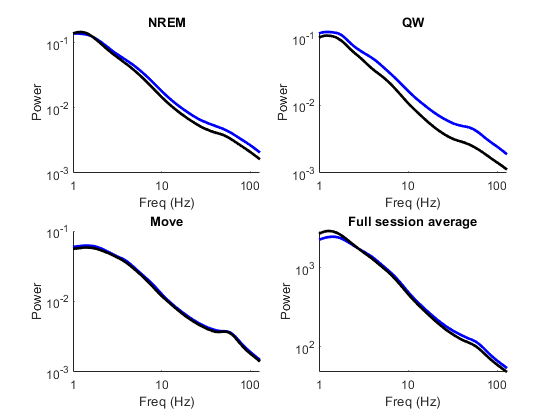

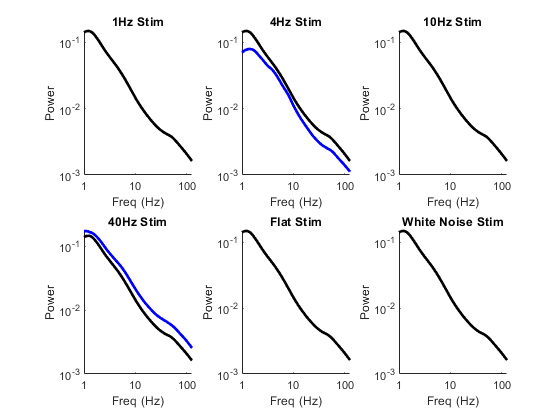

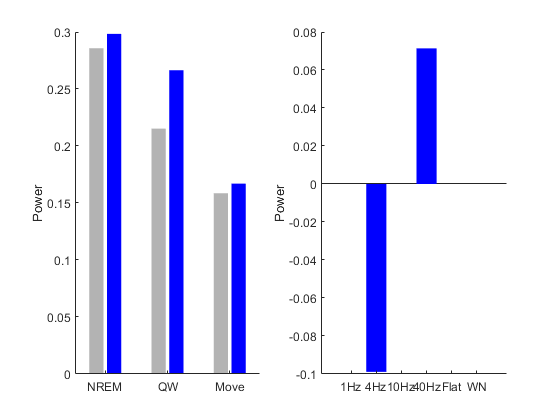

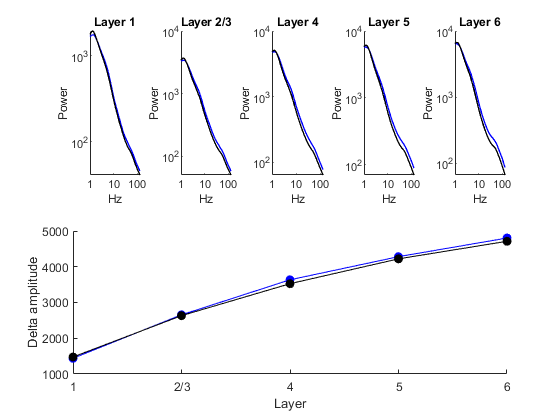

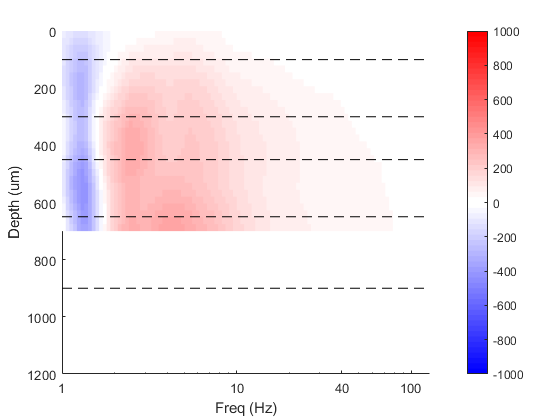

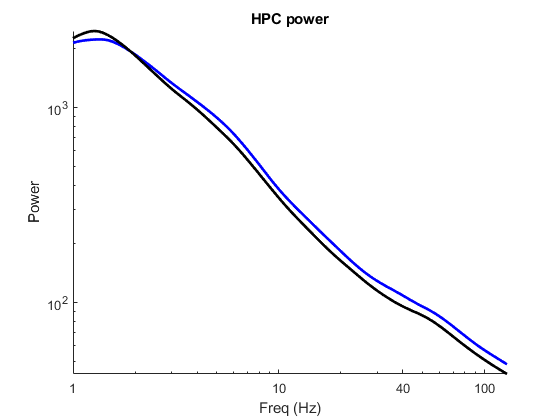

Animal7149b = struct with fields:
    ipsi: [1×1 struct]



Animal7149b.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp lfpContra

## Animal 7158

Day 2 - Session A

basepath = [serverPath '\7158\JR_23_09_11_ChR2_dual_animal_7158_session_A\JR_23_09_11_ChR2_dual_animal_7158_session_A_230911_100123'];

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


% lfpReref = lfp;
% lfpReref.data = lfp.data - median(lfp.data,2);

lfpContra = bz_GetLFP(64:127, 'basepath', basepath);

Loading Channels 64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

wspecs = calcWaveletSpectrograms(lfp, [], basepath);

Loading wavespec data...
Loading wavespec data (reref)...


power = NaN

power = NaN

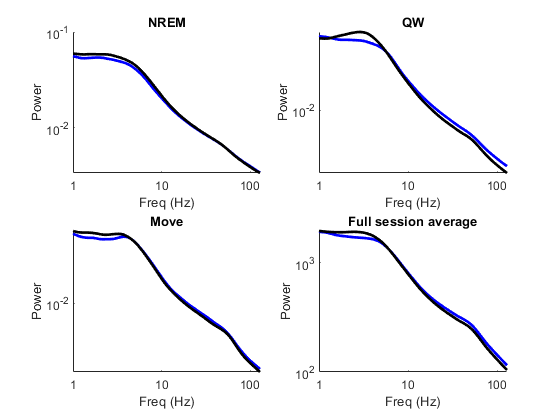

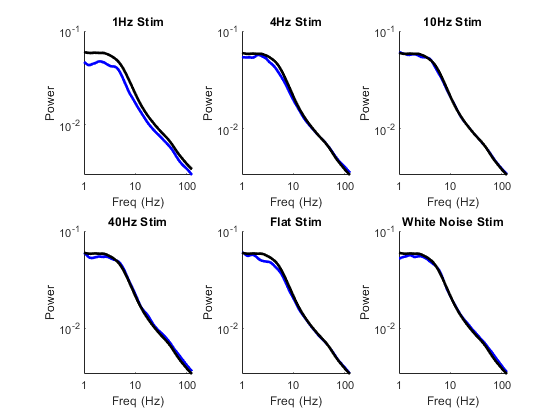

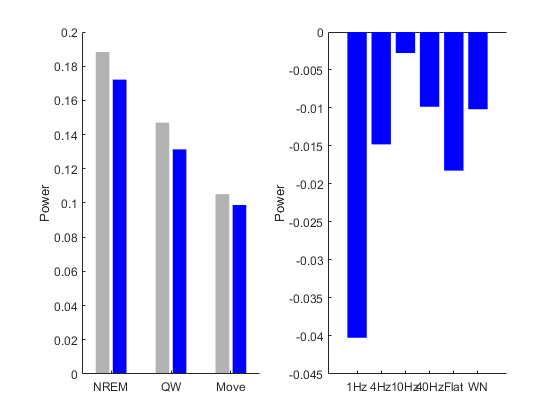

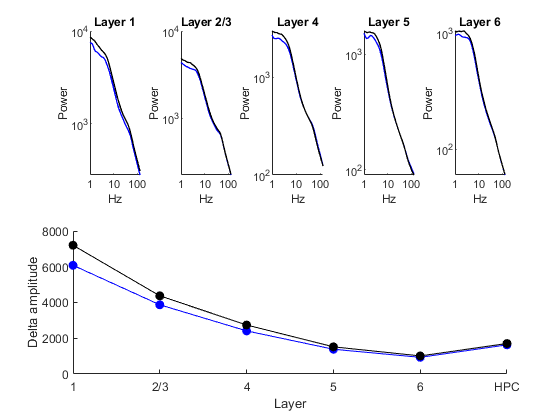

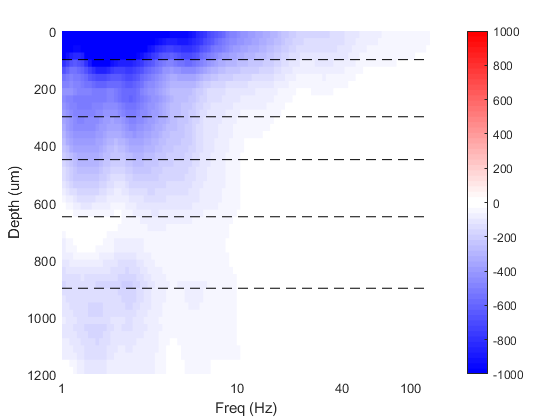

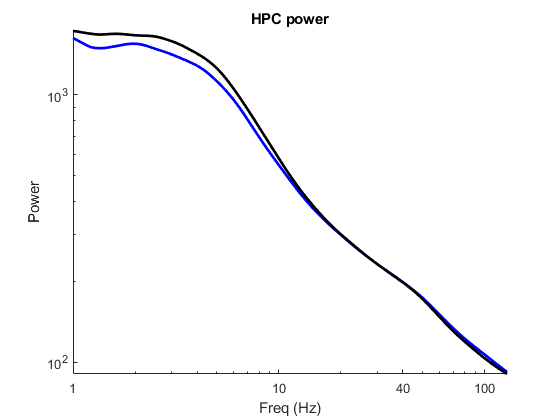

Animal7158a = struct with fields:
    ipsi: [1×1 struct]



Animal7158a.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp lfpContra

Day 3 - Session C

basepath = [serverPath '\7158\JR_23_09_12_ChR2_dual_animal_7158_session_C\JR_23_09_12_ChR2_dual_animal_7158_session_C_230912_094221'];

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


% lfpReref = lfp;
% lfpReref.data = lfp.data - median(lfp.data,2);

lfpContra = bz_GetLFP(64:127, 'basepath', basepath);

Loading Channels 64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath) - 100;
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

wspecs = calcWaveletSpectrograms(lfp, [], basepath);

Loading wavespec data...
Loading wavespec data (reref)...


power = NaN

power = NaN

power = NaN

power = NaN

power = NaN

power = NaN

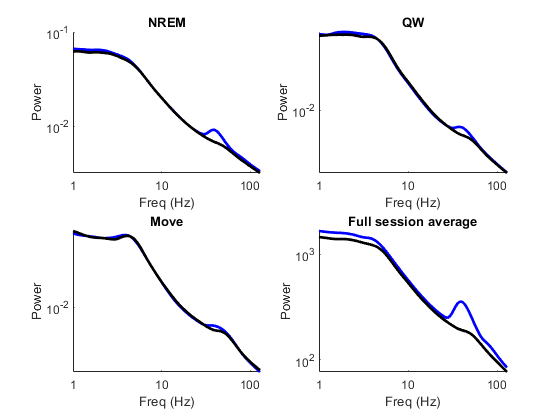

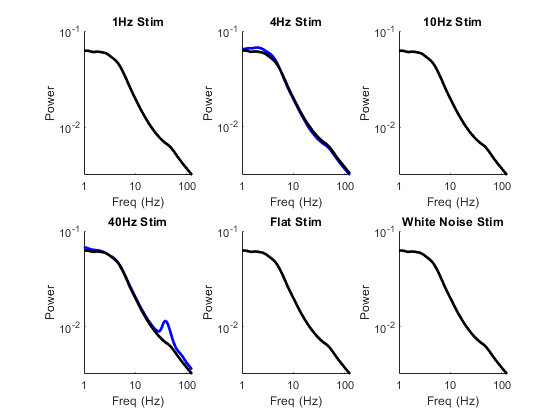

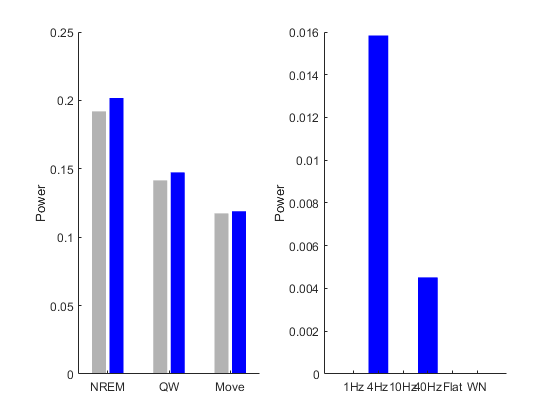

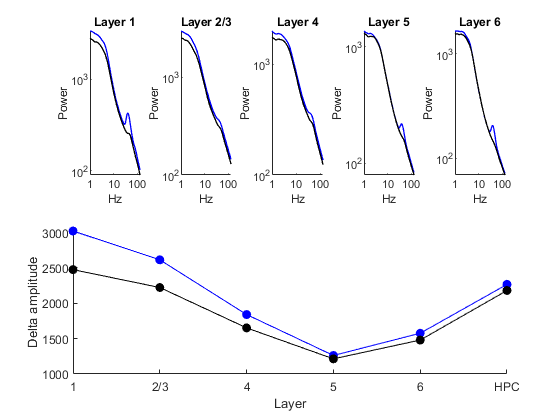

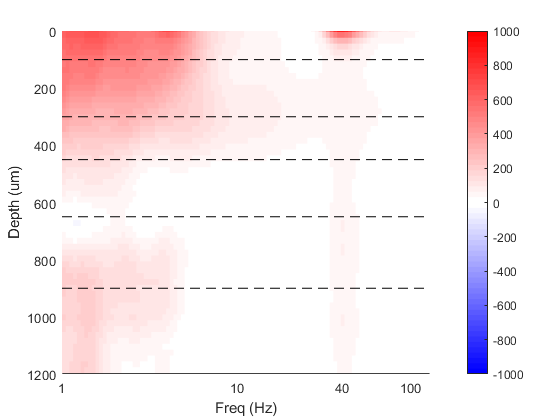

Animal7158b = struct with fields:
    ipsi: [1×1 struct]



Animal7158b.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp lfpContra

Day 4 - Session A

basepath = [serverPath '\7158\JR_23_09_13_ChR2_dual_animal_7158_session_A\JR_23_09_13_ChR2_dual_animal_7158_session_A_230913_101804'];

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


% lfpReref = lfp;
% lfpReref.data = lfp.data - median(lfp.data,2);

lfpContra = bz_GetLFP(64:127, 'basepath', basepath);

Loading Channels 64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  101  102  103  104  105  106  107  108  109  110  111  112  113  114  115  116  117  118  119  120  121  122  123  124  125  126  127 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

wspecs = calcWaveletSpectrograms(lfp, [], basepath);

Loading wavespec data...
Loading wavespec data (reref)...


power = NaN

power = NaN

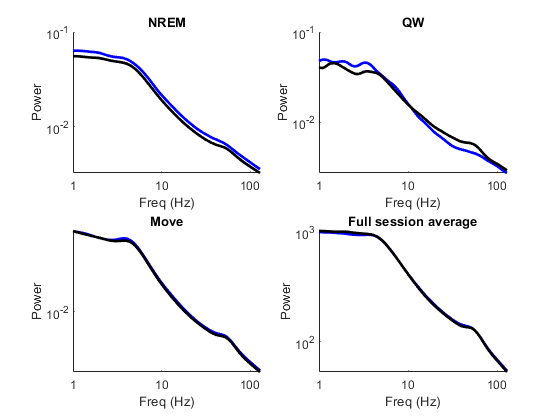

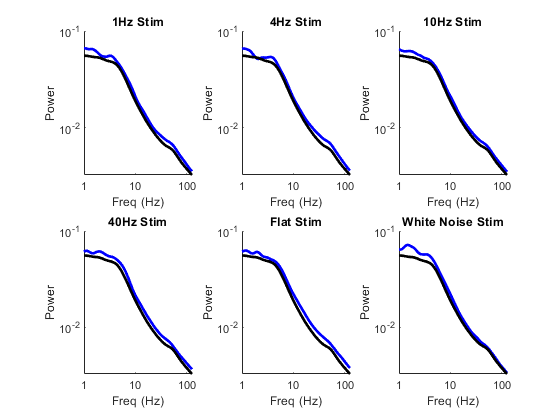

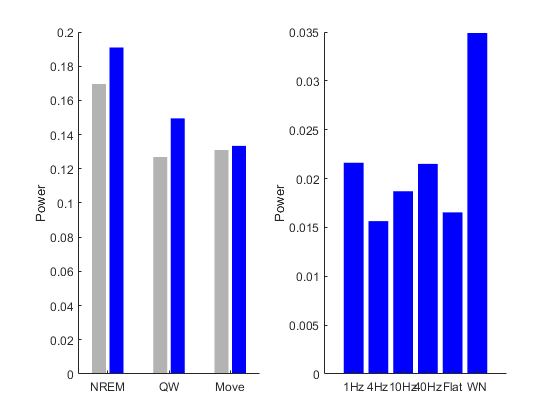

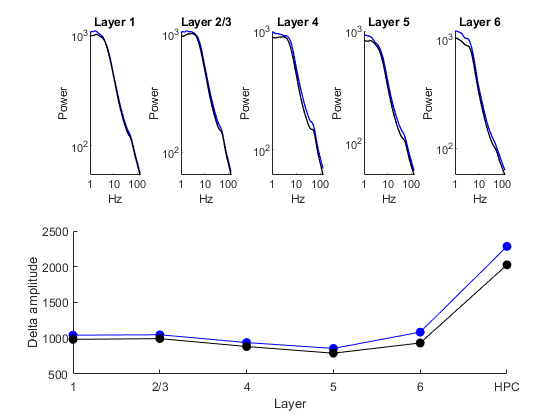

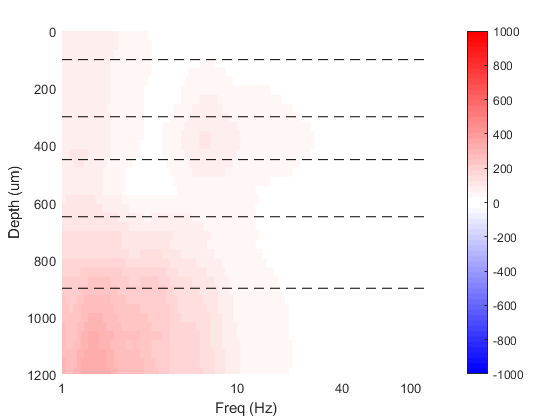

Animal7158c = struct with fields:
    ipsi: [1×1 struct]



Animal7158c.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp lfpContra

## New data for revision

data_loc = "G:\revision_opto_sessions";
optoChan_0Ind = 69;
facemotionThresh = 1000;

## Animal 6575

Day 1 - Session A - 04/15/24

basepath = data_loc + '\6575\JR_24_04_15_SSTnNOS_ChR2_6575_session_A\JR_24_04_15_SSTnNOS_ChR2_6575_session_A_240415_105602'

basepath = "G:\revision_opto_sessions\6575\JR_24_04_15_SSTnNOS_ChR2_6575_session_A\JR_24_04_15_SSTnNOS_ChR2_6575_session_A_240415_105602"


lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

badchans = co(1:5);
wspecs = calcWaveletSpectrograms(lfp, badchans, char(basepath));

Loading wavespec data...
Loading wavespec data (reref)...
Loading wavespec data (reref_fit)...


power = NaN

power = NaN

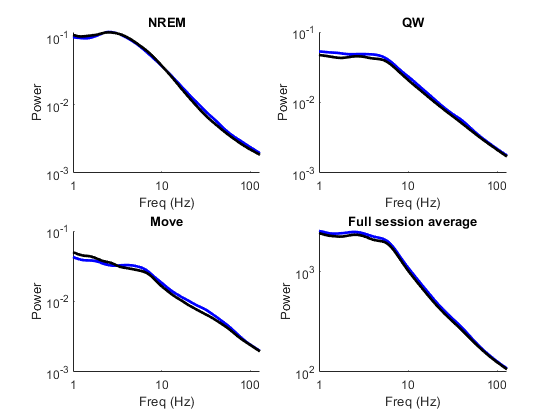

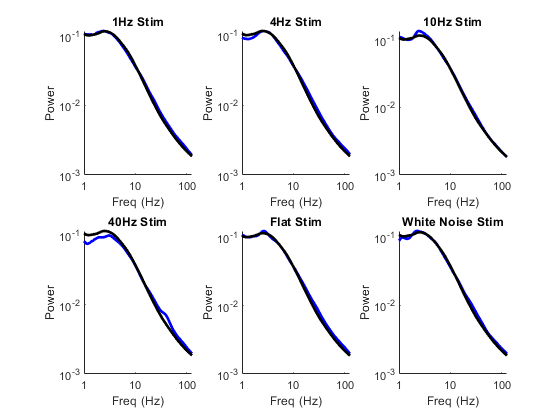

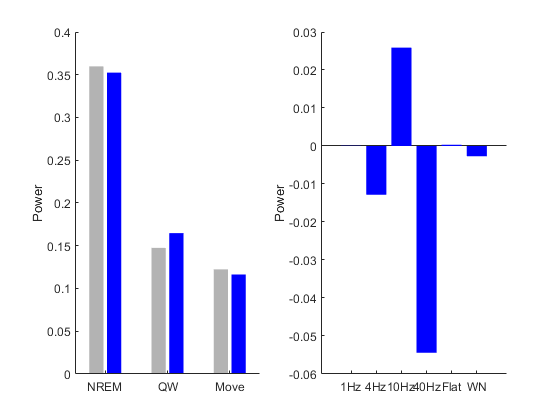

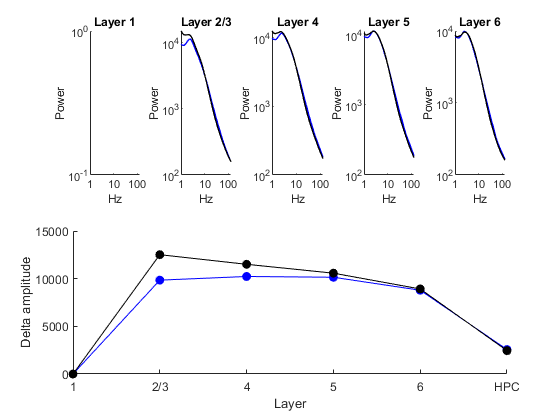

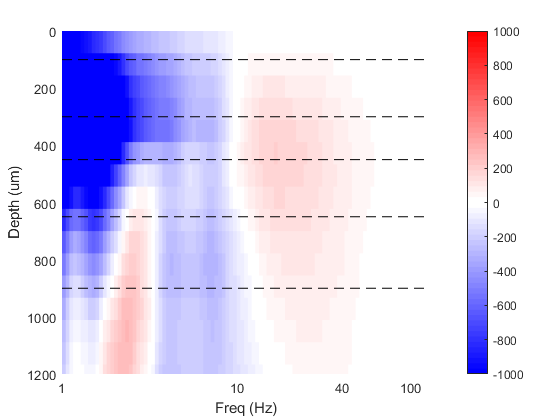

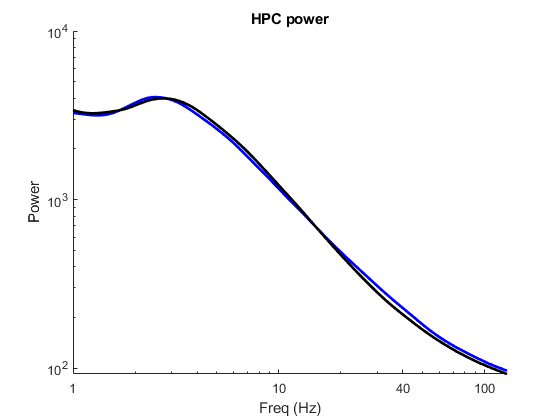

Animal6575a = struct with fields:
    ipsi: [1×1 struct]



Animal6575a.ipsi = analyzeSpectrogram(wspecs.rerefFit.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp

Day 5 - Session A - 04/19/24

basepath = data_loc + '\6575\JR_24_04_19_SSTnNOS_ChR2_6575_session_A\JR_24_04_19_SSTnNOS_ChR2_6575_session_A_240419_085822';

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

badchans = co(1:15);
wspecs = calcWaveletSpectrograms(lfp, badchans, char(basepath));

Loading wavespec data...
Loading wavespec data (reref)...
Loading wavespec data (reref_fit)...


power = NaN

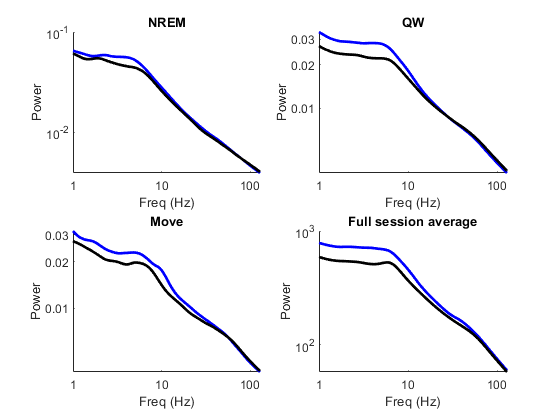

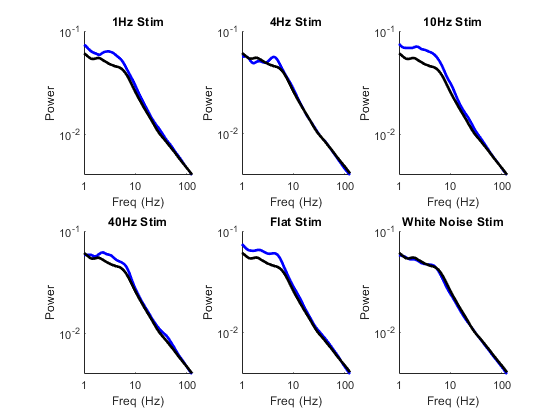

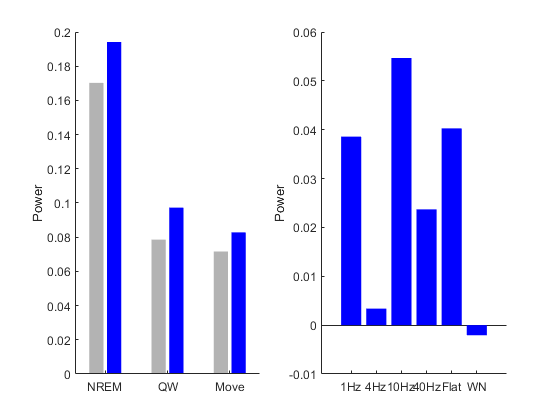

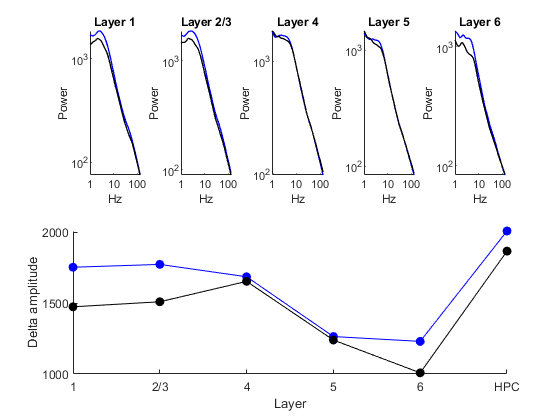

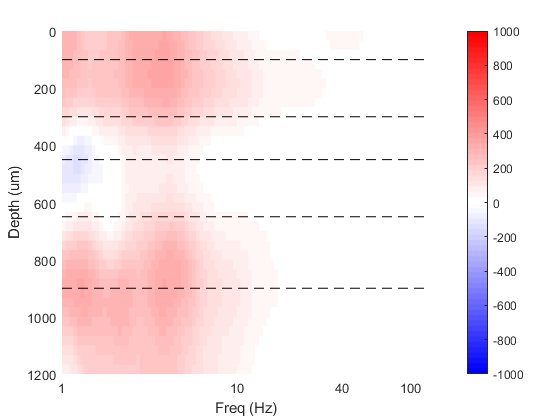

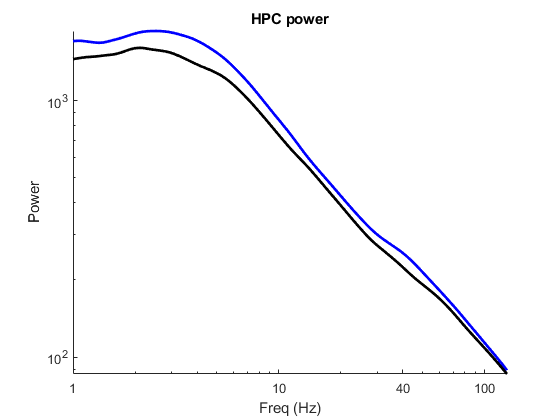

Animal6575b = struct with fields:
    ipsi: [1×1 struct]



 Animal6575b.ipsi = analyzeSpectrogram(wspecs.rerefFit.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp

## Animal 6576

Day 2 - Session A - 04/16/24

basepath = data_loc + '\6576\JR_24_04_16_SSTnNOS_ChR2_6576_session_A\JR_24_04_16_SSTnNOS_ChR2_6576_session_A_240416_103011';

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, 100);

badchans = co(1:10);
wspecs = calcWaveletSpectrograms(lfp, badchans, char(basepath));

Loading wavespec data...
Loading wavespec data (reref)...
Loading wavespec data (reref_fit)...


power = NaN

power = NaN

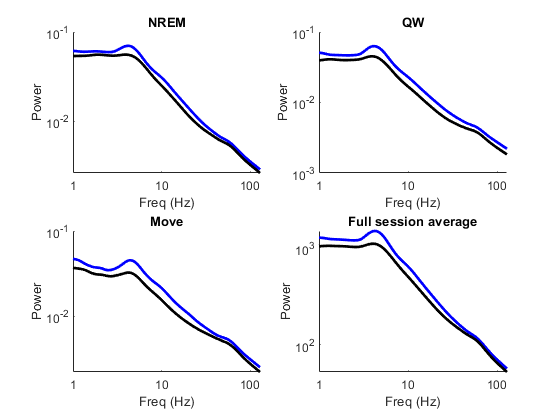

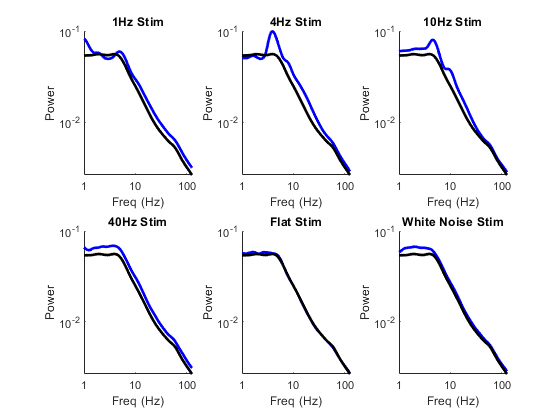

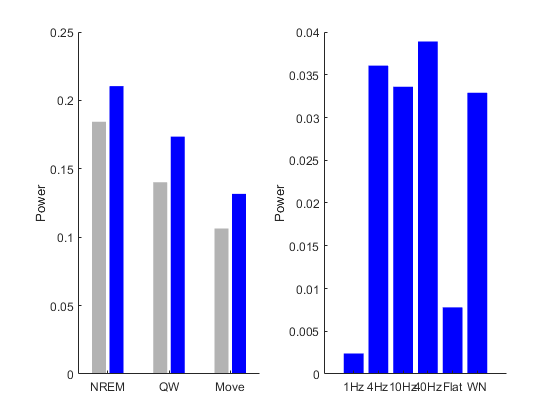

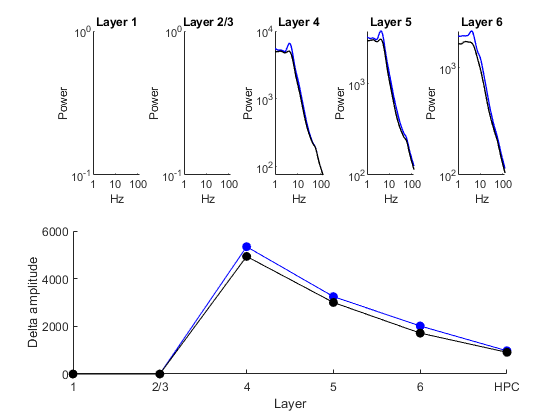

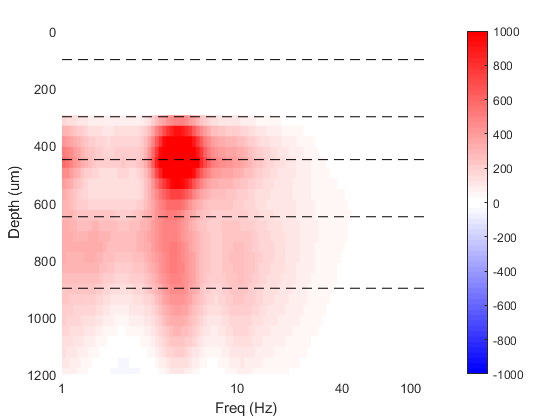

Animal6576a = struct with fields:
    ipsi: [1×1 struct]



Animal6576a.ipsi = analyzeSpectrogram(wspecs.rerefFit.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp

## Animal 6692

Day 5 - Session A - 03/29/24

basepath = data_loc + '\6692\JR_24_03_29_SSTnNOS_ChR2_6692_session_A\JR_24_03_29_SSTnNOS_ChR2_6692_session_A_240329_085446';


lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, 500);

badchans = [45 62 0 23 31 17 22]+1;
wspecs = calcWaveletSpectrograms(lfp, badchans, char(basepath));

Loading wavespec data...
Loading wavespec data (reref)...
Loading wavespec data (reref_fit)...


power = NaN

power = NaN

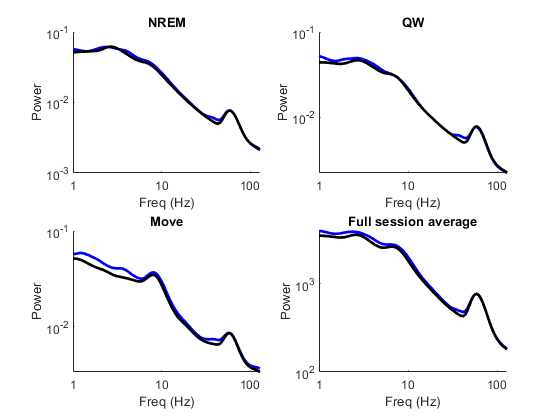

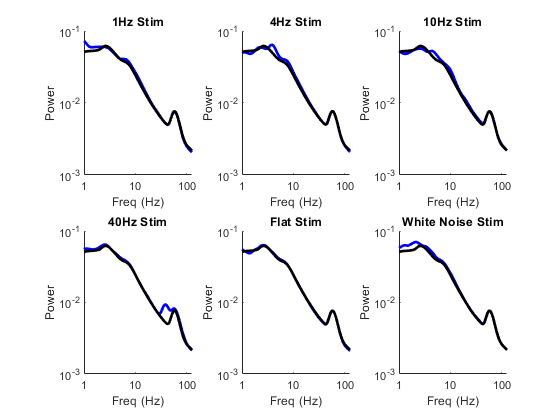

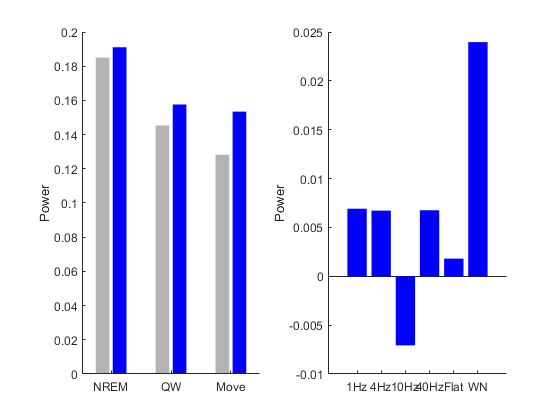

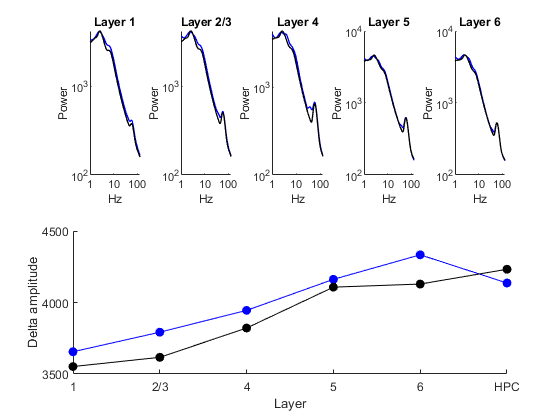

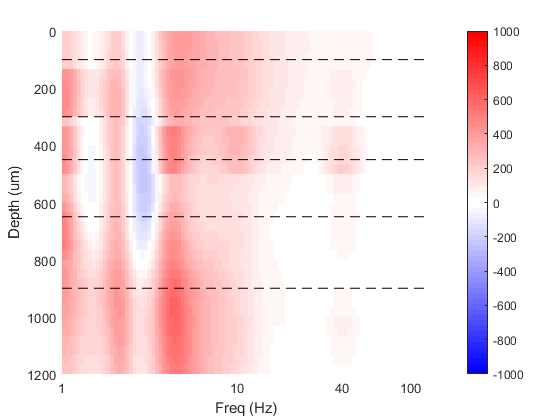

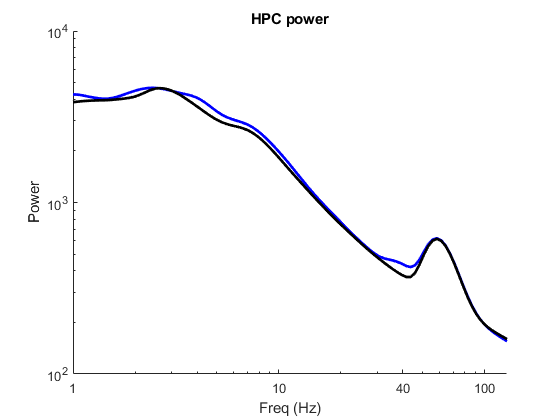

Animal6692a = struct with fields:
    ipsi: [1×1 struct]



Animal6692a.ipsi = analyzeSpectrogram(wspecs.raw.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp

Day 3 (second craniotomy) - Session A - 04/03/24

% basepath = data_loc + '\6692\JR_24_04_03_SSTnNOS_ChR2_6692_right_session_A\JR_24_04_03_SSTnNOS_ChR2_6692_right_session_A_240403_100421';

## Animal 6695

Day 4 - Session A - 03/29/24

% basepath = data_loc + '\6695\JR_24_03_29_SSTnNOS_ChR2_6695_session_A\JR_24_03_29_SSTnNOS_ChR2_6695_session_A_240329_123702';

Day 3 (second crainotomy) - Session A - 04/03/24

basepath = data_loc + '\6695\JR_24_04_03_SSTnNOS_ChR2_6695_right_session_A\JR_24_04_03_SSTnNOS_ChR2_6695_right_session_A_240403_140338';

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
% optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
load(basepath + '\' + bz_BasenameFromBasepath(basepath) + ".optostim.mat")
optoInts = getOptoInts(basepath, optostim, 200);
optoInts.NREMStim = IntersectIntervals(optoInts.NREMStim, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'WN'),:));


badchans = [45 62 0 23 31 17 22]+1;
wspecs = calcWaveletSpectrograms(lfp, badchans, char(basepath));

Loading wavespec data...
Loading wavespec data (reref)...
Loading wavespec data (reref_fit)...


power = NaN

power = NaN

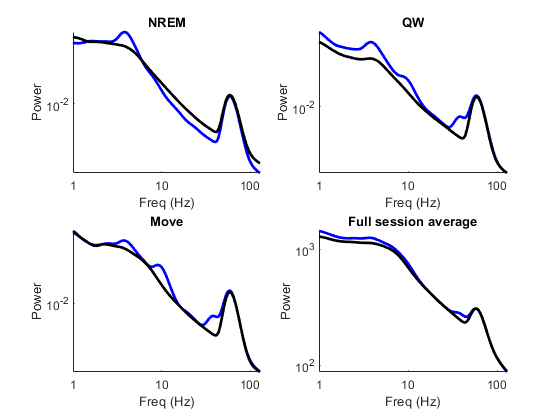

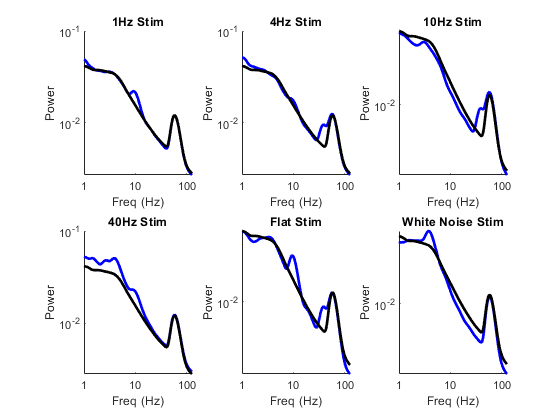

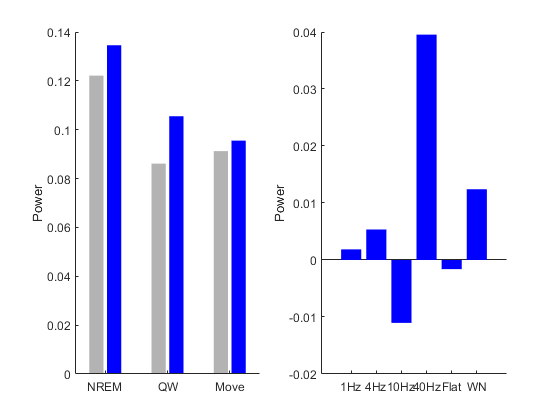

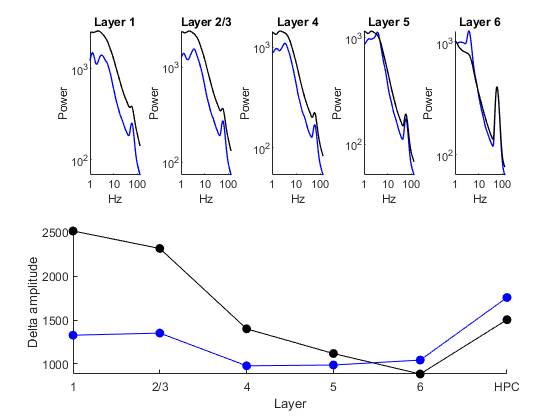

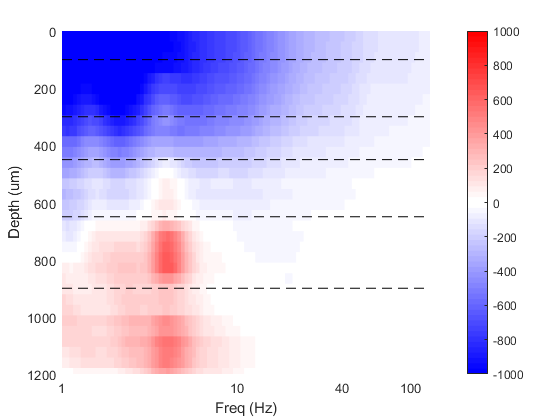

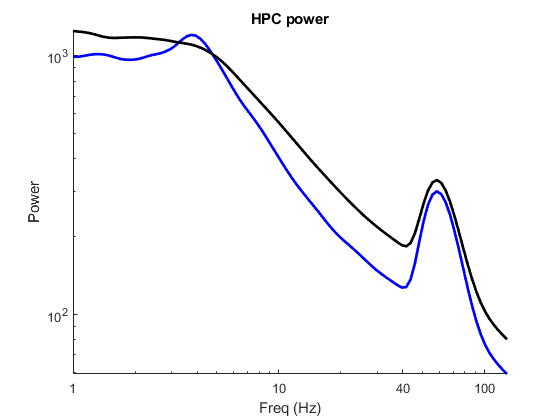

Animal6695a = struct with fields:
    ipsi: [1×1 struct]



Animal6695a.ipsi = analyzeSpectrogram(wspecs.rerefFit.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


% clearvars wspecs lfp

## Animal 6750

Day 2 - Session A - 04/16/24

basepath = data_loc + '\6750\JR_24_04_16_SSTnNOS_ChR2_6750_session_A\JR_24_04_16_SSTnNOS_ChR2_6750_session_A_240416_145805';

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');       

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, 700);

badchans = co(1:5) -1;
wspecs = calcWaveletSpectrograms(lfp, badchans, char(basepath));

Loading wavespec data...
Loading wavespec data (reref)...
Loading wavespec data (reref_fit)...


power = NaN

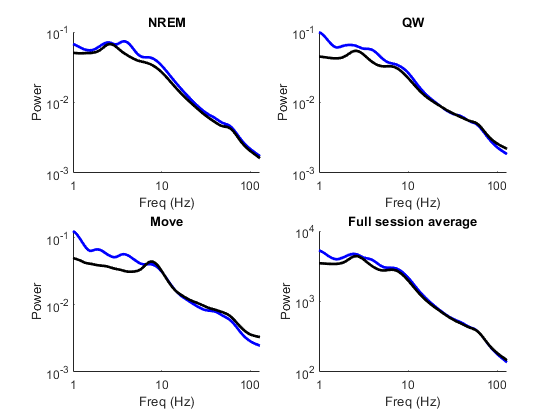

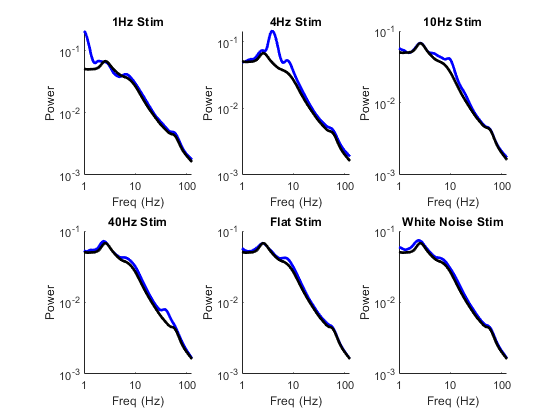

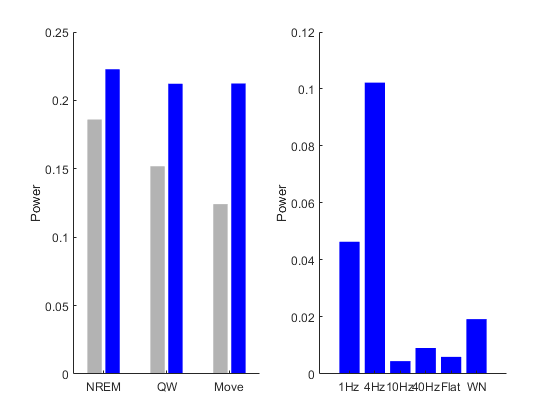

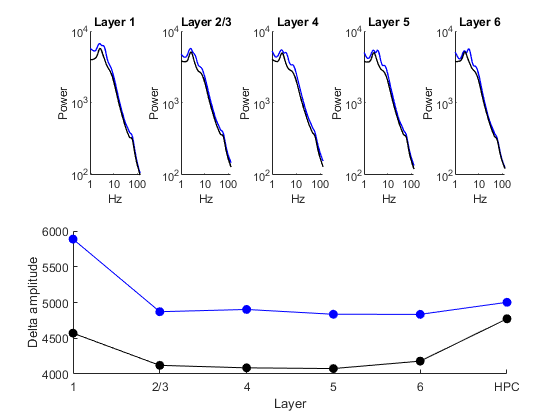

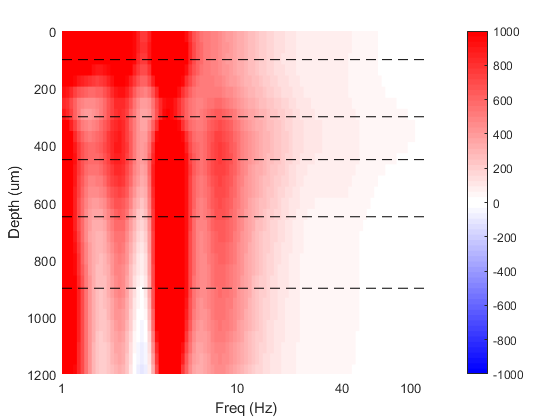

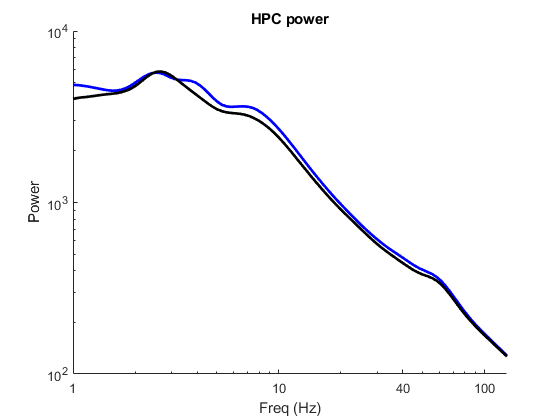

Animal6750a = struct with fields:
    ipsi: [1×1 struct]



Animal6750a.ipsi = analyzeSpectrogram(wspecs.raw.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp

## Animal 6759

Day 1 - Session A - 04/15/24

basepath = data_loc + '\6759\JR_24_04_15_SSTnNOS_ChR2_6759_session_A\JR_24_04_15_SSTnNOS_ChR2_6759_session_A_240415_145147';

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, 2500);
optoInts.NREMStim = IntersectIntervals(optoInts.NREMStim, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'WN'),:));
badchans = co(1:5) -1;
wspecs = calcWaveletSpectrograms(lfp, badchans, char(basepath));

Loading wavespec data...
Loading wavespec data (reref)...
Loading wavespec data (reref_fit)...


power = NaN

power = NaN

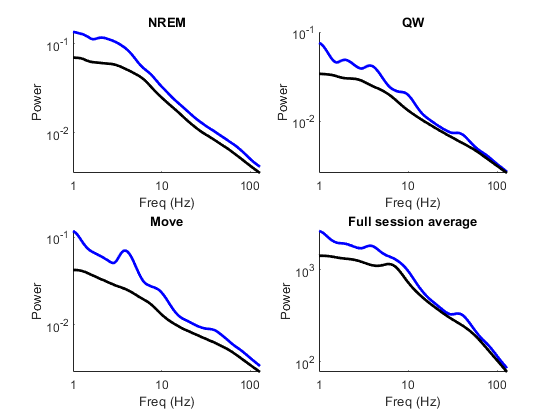

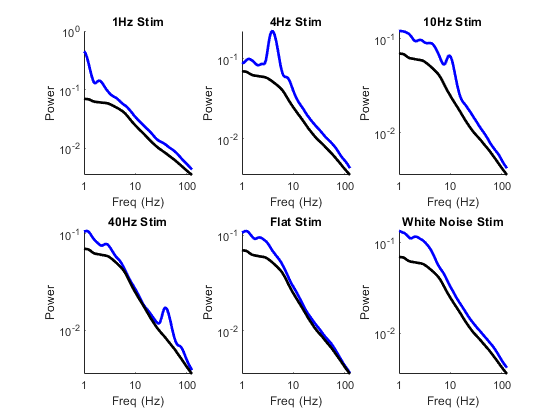

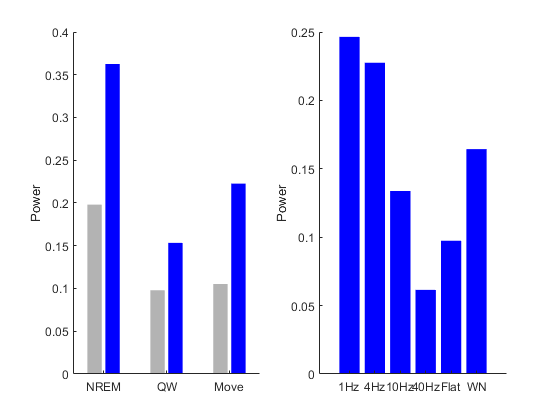

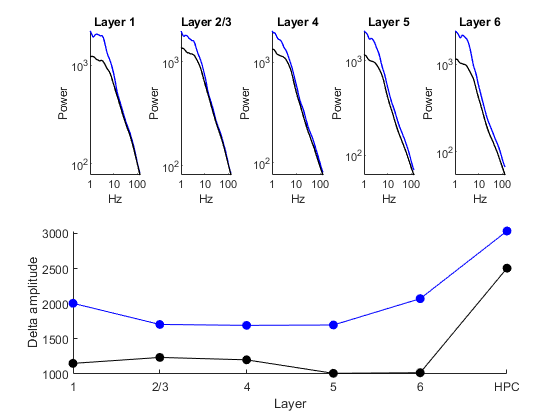

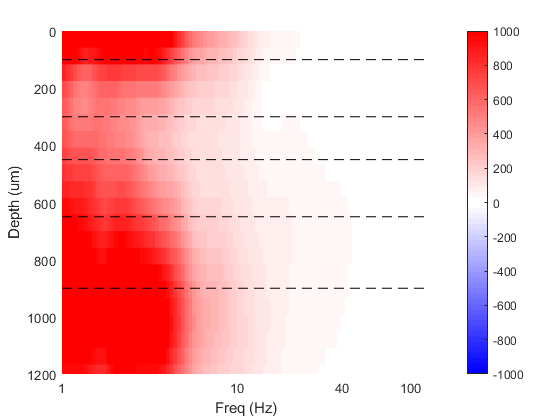

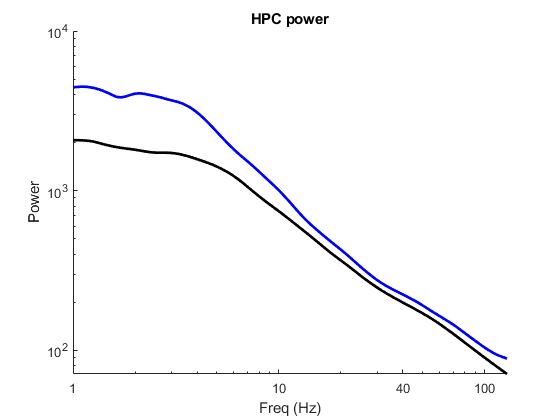

Animal6759a = struct with fields:
    ipsi: [1×1 struct]



Animal6759a.ipsi = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


clearvars wspecs lfp

Day 5 - Session A - 04/19/24

basepath = data_loc + '\6759\JR_24_04_19_SSTnNOS_ChR2_6759_session_A\JR_24_04_19_SSTnNOS_ChR2_6759_session_A_240419_131907';

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...



chanDepth_um = layerLocalization(basepath);
co = getChannelOrder2('H3');

sess = bz_getSessionInfo(basepath);
hpcChans = strcmp(sess.region(1:64), 'HPC');

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

badchans = co(1:25)-1;
wspecs = calcWaveletSpectrograms(lfp, badchans, char(basepath));

Loading wavespec data...
Loading wavespec data (reref)...
Loading wavespec data (reref_fit)...


power = NaN

power = NaN

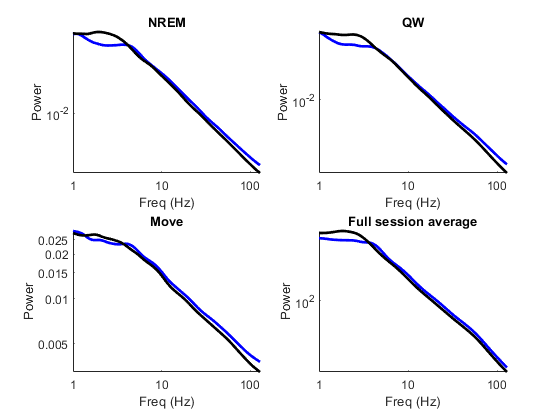

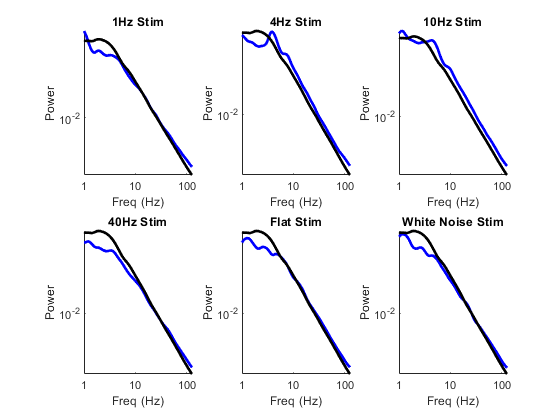

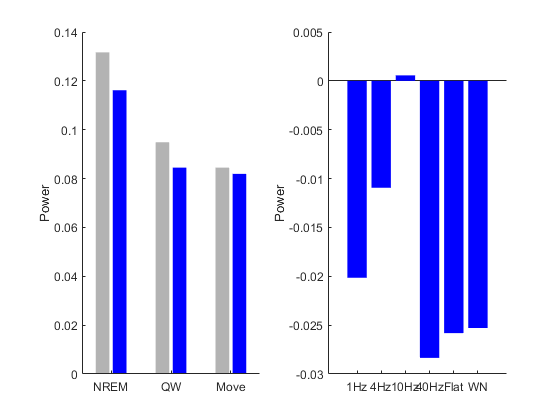

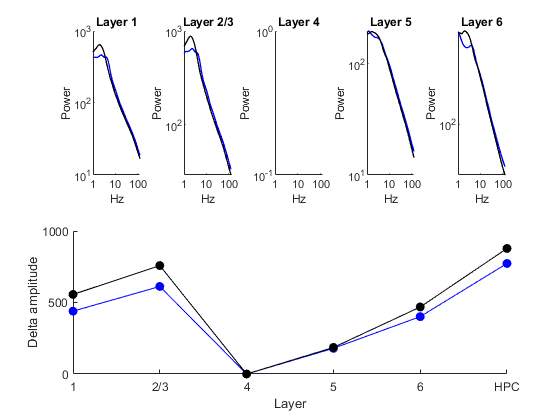

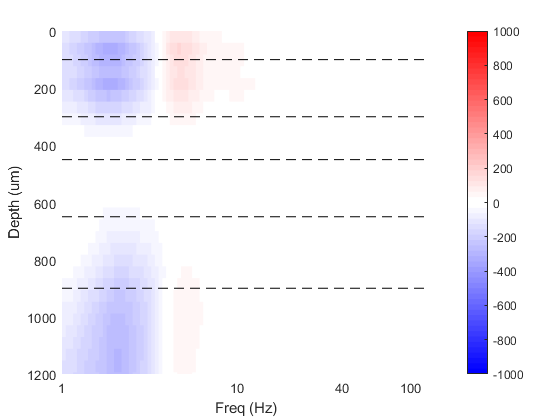

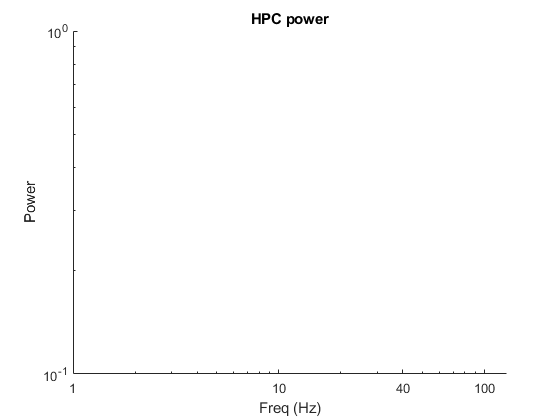

Animal6759b = struct with fields:
    ipsi: [1×1 struct]



Animal6759b.ipsi = analyzeSpectrogram(wspecs.rerefFit.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)


% clearvars wspecs lfp

% Animal6759b.ipsi = analyzeSpectrogram(wspecs.raw.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)
% figure
% surface(wspecs.reref.ipsi.freqs,1:64,Animal6759b.ipsi.laminarSpectrum.stim'./Animal6759b.ipsi.laminarSpectrum.spont','EdgeColor','none')
% set(gca,'xscale','log')

% badchans = co(1:25)-1;
% badmask = ismember(1:64,badchans);
% wspecs.raw.ipsi.data(:,:,badmask) = nan;

% test = analyzeSpectrogram(wspecs.reref.ipsi, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)

% lfpReref = lfp;
% medianlfp.data = median(lfp.data(:,~badmask),2,'omitnan');
% lfpReref.data = lfp.data - medianlfp.data;
% 

% medianlfp.timestamps = lfp.timestamps;
% medianlfp.samplingRate = lfp.samplingRate;
% medianwspec = bz_WaveSpec(medianlfp);

% figure
% plot(medianwspec.freqs,mean(abs(medianwspec.data),1))
% set(gca,'xscale','log')
% set(gca,'yscale','log')


% betaR = (single(medianlfp.data)' * single(lfp.data)) / (single(medianlfp.data') * single(medianlfp.data));
% mhat = single(medianlfp.data) * betaR;
% lfpResid = lfp;
% lfpResid.data = lfp.data - int16(mhat);


% residwspec = bz_WaveSpec(lfpResid,'chanID',co(30:5:60)-1,'showprogress',true,'saveMat',true,...
%         'saveMatPath',char(basepath),'MatNameExtraText','_resid','downsampleout',lfp.samplingRate/10);

% figure
% plot(residwspec.freqs,squeeze(mean(mean(abs(residwspec.data),1),3)))
% set(gca,'xscale','log')
% set(gca,'yscale','log')

animals = [ Animal6556b, Animal6556c, Animal6556d, Animal6560a, Animal6560b, ...
    Animal7149a, Animal7149b,  Animal7158c,...
    Animal6576a, Animal6692a,...
    Animal6695a,  Animal6759a]; %  Animal6750a, Animal6575a, Animal6575b, Animal6759b, Animal7158a, Animal7158b, Animal6556a,

clearvars layerspec laminarspec layerdelta

% Instantiate variables
statespec.stim.NREM = [];
statespec.stim.QW = [];
statespec.stim.Move = [];
statespec.stim.REM = [];
statespec.spont.NREM = [];
statespec.spont.QW = [];
statespec.spont.Move = [];
statespec.spont.REM = [];

statedelta.stim.NREM = [];
statedelta.stim.QW = [];
statedelta.stim.Move = [];
statedelta.stim.REM = [];
statedelta.spont.NREM = [];
statedelta.spont.QW = [];
statedelta.spont.Move = [];
statedelta.spont.REM = [];

stimspec.Opto0 = [];
stimspec.Opto1 = [];
stimspec.Opto4 = [];
stimspec.Opto10 = [];
stimspec.Opto40 = [];
stimspec.OptoWN = [];
stimspec.NoOpto = [];
%
% stimdelta.Opto0 = [];
% stimdelta.Opto1 = [];
% stimdelta.Opto4 = [];
% stimdelta.Opto10 = [];
% stimdelta.Opto40 = [];
% stimdelta.OptoWN = [];
% stimdelta.NoOpto = [];

hpcspec.stim = [];
spcspec.spont = [];

% Normalize power
for i = 1:length(animals)
    conds = fieldnames(animals(i).ipsi.condspec);
    conds(3:4) = [];
    for j = 1:length(conds)
        animals(i).ipsi.condspec.(conds{j}) = animals(i).ipsi.condspec.(conds{j})...
            ./ trapz(freqs,animals(i).ipsi.condspec.NoOpto);
        if length(animals(i).ipsi.condspec.(conds{j})) == 1
            animals(i).ipsi.condspec.(conds{j}) = nan(1,100);
        end
    end
end

for i = 1:length(animals)
    % Average state spectrogram (stim + spont) and delta band
    statespec.stim.NREM = [statespec.stim.NREM; animals(i).ipsi.condspec.NREMStim];
    statespec.stim.QW = [statespec.stim.QW; animals(i).ipsi.condspec.QWStim];
    statespec.stim.Move = [statespec.stim.Move; animals(i).ipsi.condspec.MoveStim];
    %     statespec.stim.REM = [statespec.stim.REM animals(i).ipsi.condspec.REMStim];
    statespec.spont.NREM = [statespec.spont.NREM; animals(i).ipsi.condspec.NREMSpont];
    statespec.spont.QW = [statespec.spont.QW; animals(i).ipsi.condspec.QWSpont];
    statespec.spont.Move = [statespec.spont.Move; animals(i).ipsi.condspec.MoveSpont];
    %     statespec.spont.REM = [statespec.spont.REM animals(i).ipsi.condspec.REMSpont];
    
    delta = trapz(deltafreqs, animals(i).ipsi.condspec.NREMStim(deltamask))/4;
    statedelta.stim.NREM = [statedelta.stim.NREM delta];
    delta = trapz(deltafreqs, animals(i).ipsi.condspec.QWStim(deltamask))/4;
    statedelta.stim.QW = [statedelta.stim.QW delta];
    delta = trapz(deltafreqs, animals(i).ipsi.condspec.MoveStim(deltamask))/4;
    statedelta.stim.Move = [statedelta.stim.Move delta];
    %     delta = trapz(deltafreqs, animals(i).ipsi.condspec.REMStim(deltamask))/4;
    %     statedelta.stim.REM = [statedelta.stim.REM delta];
    delta = trapz(deltafreqs, animals(i).ipsi.condspec.NREMSpont(deltamask))/4;
    statedelta.spont.NREM = [statedelta.spont.NREM delta];
    delta = trapz(deltafreqs, animals(i).ipsi.condspec.QWSpont(deltamask))/4;
    statedelta.spont.QW = [statedelta.spont.QW delta];
    delta = trapz(deltafreqs, animals(i).ipsi.condspec.MoveSpont(deltamask))/4;
    statedelta.spont.Move = [statedelta.spont.Move delta];
    %     delta = trapz(deltafreqs, animals(i).ipsi.condspec.REMSpont(deltamask))/4;
    %     statedelta.spont.REM = [statedelta.spont.REM delta];
    
        % Stim type spectrogram (vs no stim) and delta band
        stimspec.Opto0 = [stimspec.Opto0; animals(i).ipsi.condspec.Opto0];
        stimspec.Opto1 = [stimspec.Opto1; animals(i).ipsi.condspec.Opto1];
        stimspec.Opto4 = [stimspec.Opto4; animals(i).ipsi.condspec.Opto4];
        stimspec.Opto10 = [stimspec.Opto10; animals(i).ipsi.condspec.Opto10];
        stimspec.Opto40 = [stimspec.Opto40; animals(i).ipsi.condspec.Opto40];
        stimspec.OptoWN = [stimspec.OptoWN; animals(i).ipsi.condspec.OptoWN];
        stimspec.NoOpto = [stimspec.NoOpto; animals(i).ipsi.condspec.NoOpto];
    
%         delta = trapz(deltafreqs, animals(i).ipsi.condspec.Opto0(deltamask))/4;
%         stimdelta.Opto0 = [stimdelta.Opto0 delta];
%         delta = trapz(deltafreqs, animals(i).ipsi.condspec.Opto1(deltamask))/4;
%         stimdelta.Opto1 = [stimdelta.Opto1 delta];
%         delta = trapz(deltafreqs, animals(i).ipsi.condspec.Opto4(deltamask))/4;
%         stimdelta.Opto4 = [stimdelta.Opto4 delta];
%         delta = trapz(deltafreqs, animals(i).ipsi.condspec.Opto10(deltamask))/4;
%         stimdelta.Opto10 = [stimdelta.Opto10 delta];
%         delta = trapz(deltafreqs, animals(i).ipsi.condspec.Opto40(deltamask))/4;
%         stimdelta.Opto40 = [stimdelta.Opto40 delta];
%         delta = trapz(deltafreqs, animals(i).ipsi.condspec.OptoWN(deltamask))/4;
%         stimdelta.OptoWN = [stimdelta.OptoWN delta];
%         delta = trapz(deltafreqs, animals(i).ipsi.condspec.NoOpto(deltamask))/4;
%         stimdelta.NoOpto = [stimdelta.NoOpto delta];
    
    % Layer spectrogram and delta power
    layerspec.stim(i,:,:) = animals(i).ipsi.layerSpectrum.stim;
    layerspec.spont(i,:,:) = animals(i).ipsi.layerSpectrum.spont;
    
    layerdelta.stim(i,:) = trapz(deltafreqs, animals(i).ipsi.layerSpectrum.stim(:,deltamask), 2)/4;
    layerdelta.spont(i,:) = trapz(deltafreqs, animals(i).ipsi.layerSpectrum.spont(:,deltamask), 2)/4;
    
    % HPC spectrogram
    hpcspec.stim(i,:) = animals(i).ipsi.hpcspec.stim;
    hpcspec.spont(i,:) = animals(i).ipsi.hpcspec.spont;
end

% Full laminar power
targetDepths = 0:10:1100;
for i = 1:length(animals)
    
    laminarspec.stim(i,:,:) = interp1(animals(i).ipsi.laminarSpectrum.depth, ...
        animals(i).ipsi.laminarSpectrum.stim', targetDepths,'linear','extrap');
    laminarspec.spont(i,:,:) = interp1(animals(i).ipsi.laminarSpectrum.depth, ...
        animals(i).ipsi.laminarSpectrum.spont', targetDepths,'linear','extrap');
    
%     laminarspec.stim(i,:,:) = animals(i).ipsi.laminarSpectrum.stim;
%     laminarspec.spont(i,:,:) = animals(i).ipsi.laminarSpectrum.spont;
end

% Remove outlier
% statedelta.stim.Move(end) = [];
% statedelta.spont.Move(end) = [];

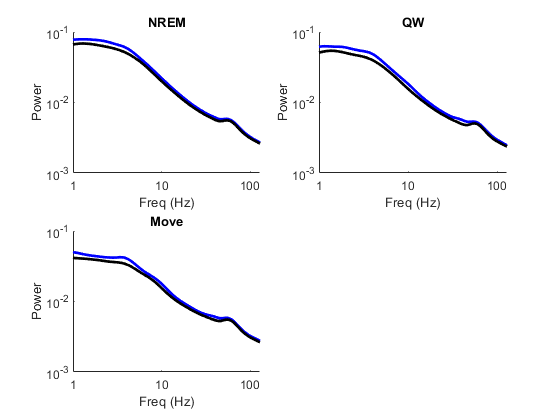

plim = [1e-3 1e-1];

figure
subplot(2,2,1); hold on
plot(freqs, mean(statespec.stim.NREM), 'b', 'linewidth', 2)
plot(freqs, mean(statespec.spont.NREM), 'k', 'linewidth', 2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
ylim(plim)
ylabel('Power')
title('NREM')

subplot(2,2,2); hold on
plot(freqs, mean(statespec.stim.QW), 'b', 'linewidth', 2)
plot(freqs, mean(statespec.spont.QW), 'k', 'linewidth', 2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
ylim(plim)
ylabel('Power')
title('QW')

subplot(2,2,3); hold on
plot(freqs, mean(statespec.stim.Move,'omitnan'), 'b', 'linewidth', 2)
plot(freqs, mean(statespec.spont.Move), 'k', 'linewidth', 2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
ylim(plim)
ylabel('Power')
title('Move')

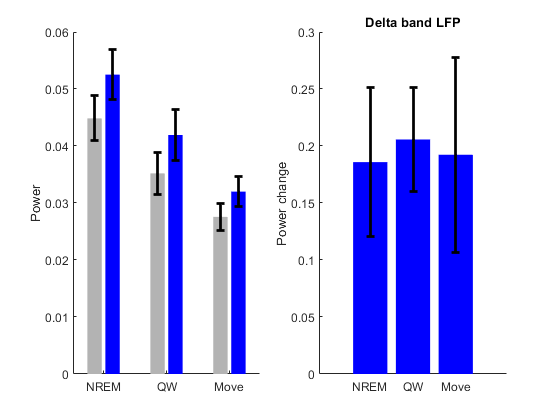

figure
subplot(1,2,1)
groupBarError([mean(statedelta.spont.NREM) mean(statedelta.spont.QW) mean(statedelta.spont.Move,'omitnan');...
    mean(statedelta.stim.NREM) mean(statedelta.stim.QW) mean(statedelta.stim.Move,'omitnan')]', ...
    [std(statedelta.spont.NREM) std(statedelta.spont.QW) std(statedelta.spont.Move,'omitnan');...
    std(statedelta.stim.NREM) std(statedelta.stim.QW) std(statedelta.stim.Move,'omitnan')]'./sqrt(length(animals)))
ylabel('Power')
xticks(1:3)
xticklabels({'NREM', 'QW', 'Move'})

subplot(1,2,2); hold on
bar([mean(statedelta.stim.NREM ./ statedelta.spont.NREM), ...
    mean(statedelta.stim.QW ./ statedelta.spont.QW),...
    mean(statedelta.stim.Move ./ statedelta.spont.Move,'omitnan')] - 1,...
    'EdgeColor','none','FaceColor','b')
errorbar(1:3, [mean(statedelta.stim.NREM ./ statedelta.spont.NREM), ...
    mean(statedelta.stim.QW ./ statedelta.spont.QW),...
    mean(statedelta.stim.Move ./ statedelta.spont.Move,'omitnan')] - 1,...
    [std(statedelta.stim.NREM ./ statedelta.spont.NREM), ...
    std(statedelta.stim.QW ./ statedelta.spont.QW),...
    std(statedelta.stim.Move ./ statedelta.spont.Move,'omitnan')]./sqrt(length(animals)),...
    'k','LineWidth',2,'LineStyle','none')
ylabel('Power change')
title('Delta band LFP')
xticks(1:3)
xticklabels({'NREM','QW','Move'})

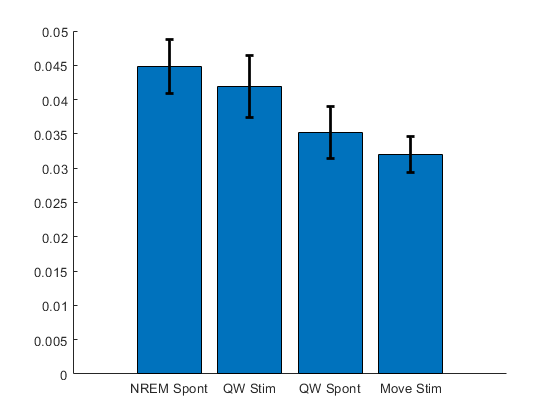

figure; hold on
bar([mean(statedelta.spont.NREM) ...
    mean(statedelta.stim.QW) ...
    mean(statedelta.spont.QW) ...
    mean(statedelta.stim.Move)])
errorbar([mean(statedelta.spont.NREM) ...
    mean(statedelta.stim.QW) ...
    mean(statedelta.spont.QW) ...
    mean(statedelta.stim.Move)], ...
    [std(statedelta.spont.NREM) ...
    std(statedelta.stim.QW) ...
    std(statedelta.spont.QW) ...
    std(statedelta.stim.Move)]./sqrt(length(animals)),...
    'k-','LineWidth',2,'linestyle','none')
xticks(1:4)
xticklabels({'NREM Spont', 'QW Stim', 'QW Spont', 'Move Stim'})

size([statedelta.spont.NREM; ...
    statedelta.stim.QW; ...
    statedelta.spont.QW;...
    statedelta.stim.Move]')

ans =     12     4



% Convert to table
T = array2table([statedelta.spont.NREM; ...
    statedelta.stim.QW; ...
    statedelta.spont.QW;...
    statedelta.stim.Move]',...
    'VariableNames', {'NREMsp';'QWst';'QWsp';'MoveSt'});

% Create repeated measures model design
within = table({'NREMsp';'QWst';'QWsp';'MoveSt'}, 'VariableNames', {'Condition'});

% Fit repeated measures model
rm = fitrm(T, 'NREMsp-MoveSt ~ 1', 'WithinDesign', within)

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [12×4 table]
         ResponseNames: {'NREMsp'  'QWst'  'QWsp'  'MoveSt'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [4×1 table]
     WithinFactorNames: {'Condition'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×4 table]
            Covariance: [4×4 table]



% Run repeated-measures ANOVA
ranovatbl = ranova(rm);

% Display results
disp(ranovatbl);

                               SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                             _________    __    __________    ______    __________    __________    __________    _________

    (Intercept):Condition     0.001262     3    0.00042067    12.099    1.6787e-05    0.00028186    7.8928e-05    0.0051631
    Error(Condition)         0.0011474    33    3.4769e-05                                                                 




posthoc = multcompare(rm, 'Condition');

disp(posthoc);

    Condition_1    Condition_2    Difference     StdErr       pValue        Lower          Upper   
    ___________    ___________    __________    _________    _________    __________    ___________

     'MoveSt'       'NREMsp'       -0.012855    0.0027007    0.0028154     -0.020982     -0.0047268
     'MoveSt'       'QWsp'        -0.0032104    0.0029349      0.70032     -0.012043      0.0056225
     'MoveSt'       'QWst'        -0.0099226    0.0030624     0.034029     -0.019139    -0.00070616
     'NREMsp'       'MoveSt'        0.012855    0.0027007    0.0028154     0.0047268       0.020982
     'NREMsp'       'QWsp'         0.0096443    0.0020732    0.0033388     0.0034048       0.015884
     'NREMsp'       'QWst'          0.002932    0.0016872    

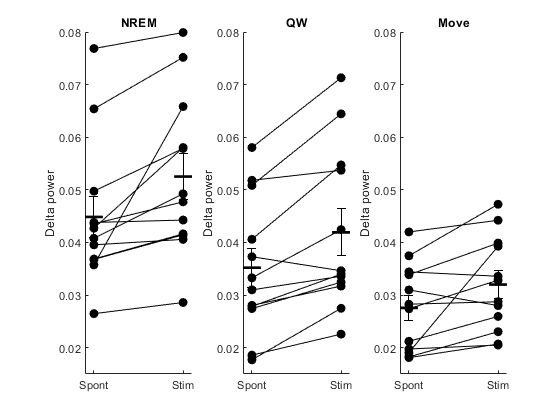

figure
subplot(1,3,1); hold on
plot(repmat([1:2], [length(statedelta.spont.NREM), 1])', ...
    [statedelta.spont.NREM; statedelta.stim.NREM],'o-','MarkerFaceColor','k','Color','k')
ylabel('Delta power')
ylim([0.015 0.08])
xlim([.9 2.1])
xticks(1:2)
xticklabels({'Spont','Stim'})
title('NREM')

plot([.9 1.1], [mean(statedelta.spont.NREM) mean(statedelta.spont.NREM)],'k', 'LineWidth',2)
plot([1.9 2.1], [mean(statedelta.stim.NREM) mean(statedelta.stim.NREM)],'k', 'LineWidth',2)

errorbar(1, mean(statedelta.spont.NREM), std(statedelta.spont.NREM)/sqrt(length(animals)),'k')
errorbar(2, mean(statedelta.stim.NREM), std(statedelta.stim.NREM)/sqrt(length(animals)),'k')

subplot(1,3,2); hold on
plot(repmat([1:2], [length(statedelta.spont.NREM), 1])', ...
    [statedelta.spont.QW; statedelta.stim.QW],'o-','MarkerFaceColor','k','Color','k')
ylabel('Delta power')
ylim([0.015 0.08])
xlim([.9 2.1])
xticks(1:2)
xticklabels({'Spont','Stim'})
title('QW')

plot([.9 1.1], [mean(statedelta.spont.QW) mean(statedelta.spont.QW)],'k', 'LineWidth',2)
plot([1.9 2.1], [mean(statedelta.stim.QW) mean(statedelta.stim.QW)],'k', 'LineWidth',2)

errorbar(1, mean(statedelta.spont.QW), std(statedelta.spont.QW)/sqrt(length(animals)),'k')
errorbar(2, mean(statedelta.stim.QW), std(statedelta.stim.QW)/sqrt(length(animals)),'k')

subplot(1,3,3); hold on
plot(repmat([1:2], [length(statedelta.spont.Move), 1])', ...
    [statedelta.spont.Move; statedelta.stim.Move],'o-','MarkerFaceColor','k','Color','k')
ylabel('Delta power')
ylim([0.015 0.08])
xlim([.9 2.1])
xticks(1:2)
xticklabels({'Spont','Stim'})
title('Move')

plot([.9 1.1], [mean(statedelta.spont.Move) mean(statedelta.spont.Move)],'k', 'LineWidth',2)
plot([1.9 2.1], [mean(statedelta.stim.Move) mean(statedelta.stim.Move)],'k', 'LineWidth',2)

errorbar(1, mean(statedelta.spont.Move), std(statedelta.spont.Move)/sqrt(length(animals)),'k')
errorbar(2, mean(statedelta.stim.Move), std(statedelta.stim.Move)/sqrt(length(animals)),'k')

% figure; hold on
% bar([mean(statedelta.stim.NREM ./ statedelta.spont.NREM), ...
%     mean(statedelta.stim.QW ./ statedelta.spont.QW),...
%     mean(statedelta.stim.Move ./ statedelta.spont.Move,'omitnan')] - 1,...
%     'EdgeColor','none','FaceColor','b')
% errorbar(1:3, [mean(statedelta.stim.NREM ./ statedelta.spont.NREM), ...
%     mean(statedelta.stim.QW ./ statedelta.spont.QW),...
%     mean(statedelta.stim.Move ./ statedelta.spont.Move,'omitnan')] - 1,...
%     [std(statedelta.stim.NREM ./ statedelta.spont.NREM), ...
%     std(statedelta.stim.QW ./ statedelta.spont.QW),...
%     std(statedelta.stim.Move ./ statedelta.spont.Move,'omitnan')]./sqrt(length(animals)),...
%     'k','LineWidth',2,'LineStyle','none')
% ylabel('Power change')
% title('Delta band LFP')
% xticks(1:3)
% xticklabels({'NREM','QW','Move'})
% 
% scatter(repelem(1:3,length(statedelta.stim.NREM)),...
%     [statedelta.stim.NREM ./ statedelta.spont.NREM ...
%     statedelta.stim.QW ./ statedelta.spont.QW...
%     statedelta.stim.Move ./ statedelta.spont.Move]-1,[],'black','filled')



yl = [-.2 1]

yl =    -0.2000    1.0000


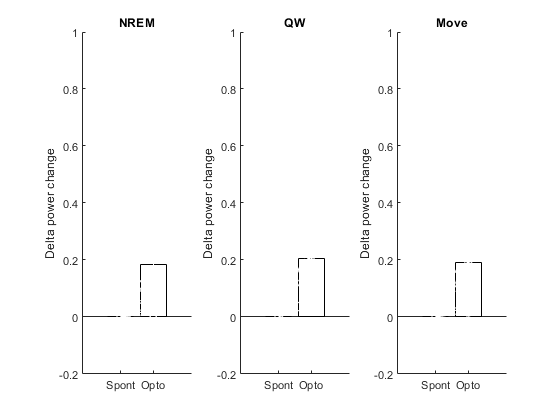


figure
subplot(1,3,1); hold on
bar([0 mean(statedelta.stim.NREM ./ statedelta.spont.NREM)-1],'FaceColor','none')
plot([zeros(size(statedelta.spont.NREM));...
     statedelta.stim.NREM ./ statedelta.spont.NREM - 1],...
    'wo--')
errorbar(2, mean(statedelta.stim.NREM ./ statedelta.spont.NREM)-1, ...
    std(statedelta.stim.NREM ./ statedelta.spont.NREM)/sqrt(length(animals)),'w')
ylabel('Delta power change')
ylim(yl)
xticks(1:2)
xticklabels({'Spont', 'Opto'})
title('NREM')

subplot(1,3,2); hold on
bar([0 mean(statedelta.stim.QW ./ statedelta.spont.QW)-1],'FaceColor','none')
plot([zeros(size(statedelta.spont.QW));...
     statedelta.stim.QW ./ statedelta.spont.QW - 1],...
    'wo--')
errorbar(2, mean(statedelta.stim.QW ./ statedelta.spont.QW)-1, ...
    std(statedelta.stim.QW ./ statedelta.spont.QW)/sqrt(length(animals)),'w')
ylabel('Delta power change')
ylim(yl)
xticks(1:2)
xticklabels({'Spont', 'Opto'})
title('QW')

subplot(1,3,3); hold on
bar([0 mean(statedelta.stim.Move ./ statedelta.spont.Move)-1],'FaceColor','none')
plot([zeros(size(statedelta.spont.Move));...
     statedelta.stim.Move ./ statedelta.spont.Move - 1],...
    'wo--')
errorbar(2, mean(statedelta.stim.Move ./ statedelta.spont.Move)-1, ...
    std(statedelta.stim.Move ./ statedelta.spont.Move)/sqrt(length(animals)),'w')
ylabel('Delta power change')
ylim(yl)
xticks(1:2)
xticklabels({'Spont', 'Opto'})
title('Move')

savepath = 'D:\EinsteinMed Dropbox\Jacob Ratliff\Jacob\data and docs\MATLAB\live_scripts\Dual_probe_ChR2_summer_2023\Revisions'

savepath = 'D:\EinsteinMed Dropbox\Jacob Ratliff\Jacob\data and docs\MATLAB\live_scripts\Dual_probe_ChR2_summer_2023\Revisions'

save(fullfile(savepath,'Delta_spont_vs_opto.mat'), 'statedelta')

% dataMat = [statedelta.stim.NREM; statedelta.stim.QW; statedelta.stim.Move;...
%     statedelta.spont.NREM; statedelta.spont.QW; statedelta.spont.Move;]'
% p = anova1(dataMat);
% disp('ANOVA on delta band power:')
% p
% multcompare(stats,'Display','off')

disp('t-test comparing delta power change during NREM:')

t-test comparing delta power change during NREM:


[h p] = ttest(statedelta.stim.NREM, statedelta.spont.NREM)

h = 1

p = 0.0080


disp('t-test comparing delta power change during QW:')

t-test comparing delta power change during QW:


[h p] = ttest(statedelta.stim.QW, statedelta.spont.QW)

h = 1

p = 0.0011


disp('t-test comparing delta power change during Move:')

t-test comparing delta power change during Move:


[h p] = ttest(statedelta.stim.Move, statedelta.spont.Move)

h = 1

p = 0.0274

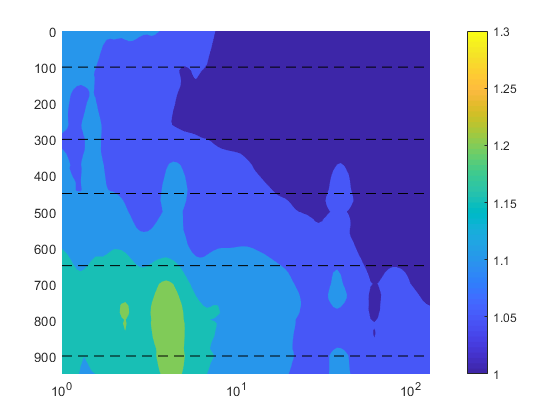

figure; hold on
contourf(targetDepths,freqs, squeeze(mean(laminarspec.stim, 1,'omitnan') ./ mean(laminarspec.spont, 1,'omitnan'))','EdgeColor','none')
view([90 90])
set(gca, 'yscale','log')
colorbar
xlim([0 950])


for i = 1:size(layerBorders,1)
    plot3([layerBorders(i,2) layerBorders(i,2)], ylim, [max(zlim) max(zlim)], 'k--')
end
clim([1 1.3])

figure; hold on
[m, c] = contourf(...
    targetDepths,freqs, ...
    smoothdata(squeeze(mean(laminarspec.stim, 1,'omitnan') ./ mean(laminarspec.spont, 1,'omitnan'))',1,'gaussian',.5,'SamplePoints',freqs)...
    ,'EdgeColor','none')

m = 	1.0e+03 *

    0.0010         0    0.0056    0.0100    0.0200    0.0300    0.0382    0.0400    0.0429    0.0400    0.0300    0.0200    0.0177    0.0100         0    0.0010    0.2570    0.2500    0.2467    0.2406    0.2400    0.2322    0.2300    0.2200    0.2121    0.2100    0.2000    0.1900    0.1855    0.1800    0.1700    0.1668    0.1600    0.1500    0.1442    0.1400    0.1300    0.1232    0.1200    0.1100    0.1037    0.1000    0.0900    0.0800    0.0700    0.0636    0.0600    0.0500    0.0400    0.0300
    0.0140    0.0326    0.0325    0.0323    0.0318    0.0313    0.0309    0.0304    0.0294    0.0292    0.0286    0.0281    0.0280    0.0277    0.0273    0.0370    0.1280    0.1239    0.1219    0.1160    0.1156    0.1105    0.1097    0.1068    0.1052    0.1049    0.1032    0.1012    0.1002    0.0990    0.0963    0.0954    0.0940    0.0919    0.0908    0.0900    0.0881    0.0865    0.0858    0.0833    0.0823    0.0819    0.0808    0.0797    0.0788    0.0784    0.0782    0.0775   

c =   Contour with properties:

    LineColor: 'none'
    LineStyle: '-'
    LineWidth: 0.5000
         Fill: 'on'
    LevelList: [0.9212 0.9500 1 1.0500 1.1000 1.1500 1.2000]
        XData: [1×111 double]
        YData: [1×100 double]
        ZData: [100×111 double]

  Show all properties


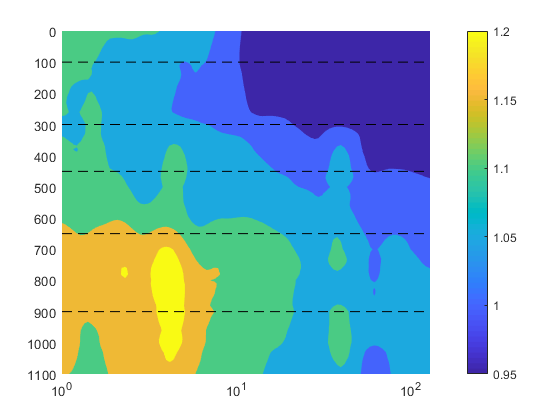

view([90 90])
set(gca, 'yscale','log')
colorbar
clim([.95 1.2])

for i = 1:size(layerBorders,1)
    plot3([layerBorders(i,2) layerBorders(i,2)], ylim, [max(zlim) max(zlim)], 'k--')
end

m

m = 	1.0e+03 *

    0.0010         0    0.0056    0.0100    0.0200    0.0300    0.0382    0.0400    0.0429    0.0400    0.0300    0.0200    0.0177    0.0100         0    0.0010    0.2570    0.2500    0.2467    0.2406    0.2400    0.2322    0.2300    0.2200    0.2121    0.2100    0.2000    0.1900    0.1855    0.1800    0.1700    0.1668    0.1600    0.1500    0.1442    0.1400    0.1300    0.1232    0.1200    0.1100    0.1037    0.1000    0.0900    0.0800    0.0700    0.0636    0.0600    0.0500    0.0400    0.0300
    0.0140    0.0326    0.0325    0.0323    0.0318    0.0313    0.0309    0.0304    0.0294    0.0292    0.0286    0.0281    0.0280    0.0277    0.0273    0.0370    0.1280    0.1239    0.1219    0.1160    0.1156    0.1105    0.1097    0.1068    0.1052    0.1049    0.1032    0.1012    0.1002    0.0990    0.0963    0.0954    0.0940    0.0919    0.0908    0.0900    0.0881    0.0865    0.0858    0.0833    0.0823    0.0819    0.0808    0.0797    0.0788    0.0784    0.0782    0.0775   

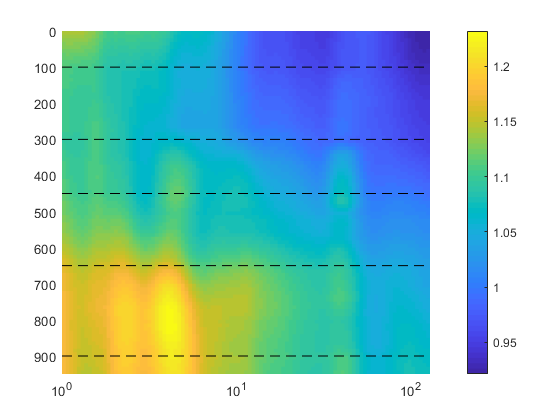

figure; hold on
surface(targetDepths,freqs, squeeze(mean(laminarspec.stim, 1,'omitnan') ./ mean(laminarspec.spont, 1,'omitnan'))','EdgeColor','none')
view([90 90])
set(gca, 'yscale','log')
colorbar
xlim([0 950])
for i = 1:size(layerBorders,1)
    plot3([layerBorders(i,2) layerBorders(i,2)], ylim, [max(zlim) max(zlim)], 'k--')
end

% for i = 1:length(animals)
%     figure
%     contourf(targetDepths,freqs, squeeze(laminarspec.stim(i,:,:) ./ laminarspec.spont(i,:,:))','edgecolor','none')
% end

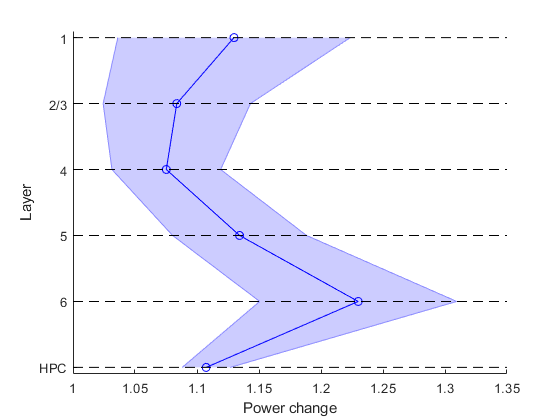

figure ; hold on
% errorbar(1:5,mean(layerdelta.stim - layerdelta.spont,'omitnan'), std(layerdelta.stim - layerdelta.spont,'omitnan')./sqrt(length(animals)),...
%     'bo-','LineWidth',2,'MarkerFaceColor','b')
shadedErrorBar(1:6,mean(layerdelta.stim ./ layerdelta.spont,'omitnan'), std(layerdelta.stim ./ layerdelta.spont,'omitnan')./sqrt(length(animals)),...
    'lineprops','bo-')
xlim([.9 6.1])
ylim([1 max(ylim)])
box off
xticks(1:6)
xticklabels({'1','2/3','4','5','6', 'HPC'})
xlabel('Layer')
ylabel('Power change')
view([90 90])
plot([1 1], ylim,'k--')
plot([2 2], ylim,'k--')
plot([3 3], ylim,'k--')
plot([4 4], ylim,'k--')
plot([5 5], ylim,'k--')
plot([6 6], ylim,'k--')

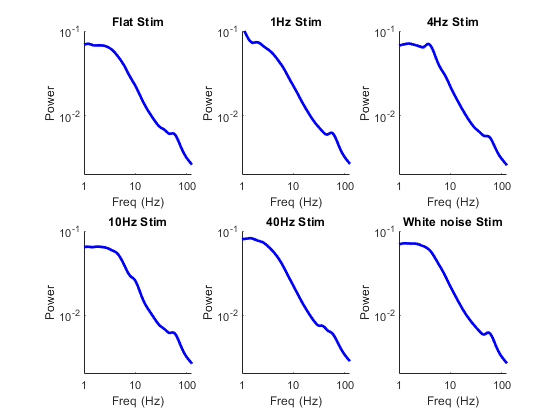

plim = [2e-3 1e-1];

figure
subplot(2,3,1); hold on
plot(freqs, mean(stimspec.Opto0,'omitnan'), 'b', 'linewidth', 2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
ylim(plim)
ylabel('Power')
title('Flat Stim')

subplot(2,3,2); hold on
plot(freqs, mean(stimspec.Opto1,'omitnan'), 'b', 'linewidth', 2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
ylim(plim)
ylabel('Power')
title('1Hz Stim')

subplot(2,3,3); hold on
plot(freqs, mean(stimspec.Opto4,'omitnan'), 'b', 'linewidth', 2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
ylim(plim)
ylabel('Power')
title('4Hz Stim')

subplot(2,3,4); hold on
plot(freqs, mean(stimspec.Opto10,'omitnan'), 'b', 'linewidth', 2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
ylim(plim)
ylabel('Power')
title('10Hz Stim')

subplot(2,3,5); hold on
plot(freqs, mean(stimspec.Opto40,'omitnan'), 'b', 'linewidth', 2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
ylim(plim)
ylabel('Power')
title('40Hz Stim')

subplot(2,3,6); hold on
plot(freqs, mean(stimspec.OptoWN,'omitnan'), 'b', 'linewidth', 2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
ylim(plim)
ylabel('Power')
title('White noise Stim')

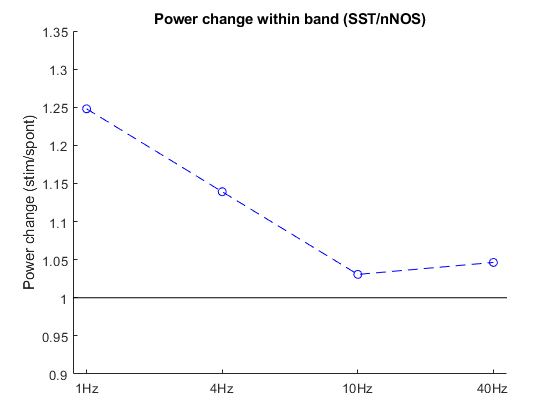

narrowBandLims = [1 2; 2 6; 7 12; 30 50];
wideBandLims = [1 6; 1 10; 5 20; 20 80];
% sinmat = [Animal6560.ipsi.condspec.Opto1;...
%     Animal6560.ipsi.condspec.Opto4;...
%     Animal6560.ipsi.condspec.Opto10;...
%     Animal6560.ipsi.condspec.Opto40];
sinOptoMat = cat(3,stimspec.Opto1,stimspec.Opto4,stimspec.Opto10, stimspec.Opto40);

clearvars bandmask widebandmask
bandstim = [];
bandspont = [];
widebandstim = [];

for i = 1:size(narrowBandLims,1)
    bandmask(i,:) = freqs > narrowBandLims(i,1) & freqs < narrowBandLims(i,2);
    widebandmask(i,:) = freqs > wideBandLims(i,1) & freqs < wideBandLims(i,2);
    bandstim(i,:) = nanmean(sinOptoMat(:,bandmask(i,:),i),2);
    bandspont(i,:) = nanmean(stimspec.NoOpto(:,bandmask(i,:)),2);
    widebandstim(i,:) = nanmean(sinOptoMat(:,widebandmask(i,:),i),2);
end

bandstim(bandstim == 0) = nan;

yl = [.9 1.35];

figure; hold on
plot(1:4,nanmean(bandstim(:,[2:6 8])./bandspont(:,[2:6 8]),2),'bo--')
ylim(yl)
xlim([.9 4.1])
plot(xlim,[1 1],'k')
ylabel('Power change (stim/spont)')
xticks(1:4)
xticklabels({'1Hz','4Hz','10Hz','40Hz'})
title('Power change within band (SST/nNOS)')

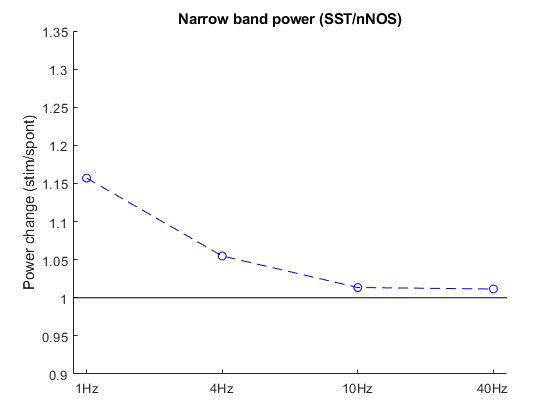


figure; hold on
plot(1:4,nanmean(bandstim(:,[2:6 8])./widebandstim(:,[2:6 8]),2),'bo--')
ylim(yl)
xlim([.9 4.1])
plot(xlim,[1 1],'k')
ylabel('Power change (stim/spont)')
xticks(1:4)
xticklabels({'1Hz','4Hz','10Hz','40Hz'})
title('Narrow band power (SST/nNOS)')

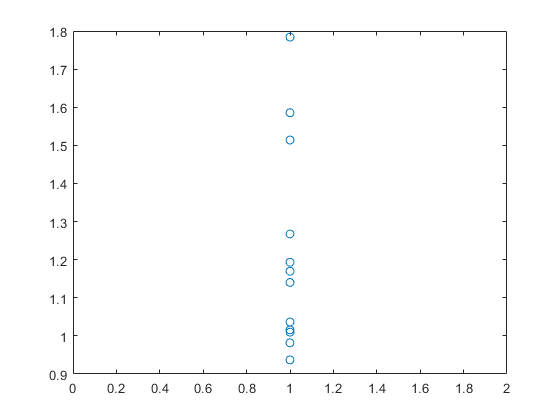


figure
plot(ones(1,length(animals)), bandstim(4,:)./bandspont(4,:),'o')

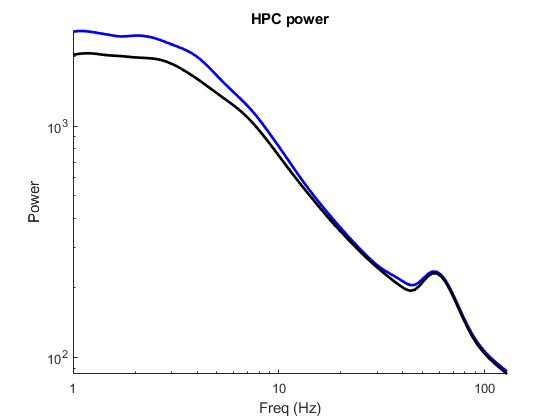

figure; hold on
title('HPC power')
plot(freqs, nanmean(hpcspec.stim), 'b','LineWidth',2)
plot(freqs, nanmean(hpcspec.spont), 'k','LineWidth',2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
ylabel('Power')

function output = analyzeSpectrogram(wspec, chanDepth_um, optostim, optoInts, layerBorders, hpcChans)

% Blank data from bad channels
badchans = [];

% Plot power spectrum across states for cortical channels
chanmask = chanDepth_um(1,:) < layerBorders(5,2) & chanDepth_um(1,:) > layerBorders(3,2); % deep layers
co = getChannelOrder2('H3');

conditions = fieldnames(optoInts);
for i = 1:length(conditions)
    [~, condmask] = RestrictInts(wspec.timestamps, optoInts.(conditions{i}));
    condSpec.(conditions{i}) = nanmean(nanmean(abs(wspec.data(condmask,:,co(chanmask))),1),3) ...
        ./ trapz(wspec.freqs, nanmean(nanmean(abs(wspec.data(:,:,co(chanmask))),1),3));
    condDelta.(conditions{i}) = nanbandpower(condSpec.(conditions{i}), wspec.freqs,...
        [1 4],'psd');
end

plim = [70 6000];

figure
subplot(2,2,1); hold on
plot(wspec.freqs, condSpec.NREMStim,'b','LineWidth',2)
plot(wspec.freqs, condSpec.NREMSpont,'k','LineWidth',2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
% ylim(plim)
ylabel('Power')
title('NREM')

subplot(2,2,2); hold on
plot(wspec.freqs, condSpec.QWStim,'b','LineWidth',2)
plot(wspec.freqs, condSpec.QWSpont,'k','LineWidth',2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
% ylim(plim)
ylabel('Power')
title('QW')

subplot(2,2,3); hold on
plot(wspec.freqs, condSpec.MoveStim,'b','LineWidth',2)
plot(wspec.freqs, condSpec.MoveSpont,'k','LineWidth',2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
% ylim(plim)
ylabel('Power')
title('Move')

% Plot power spectrum stim vs no stim
[~, stimmask] = RestrictInts(wspec.timestamps, optostim.longStimInts);
[~, spontmask] = RestrictInts(wspec.timestamps, optostim.spontInts);

subplot(2,2,4); hold on
plot(wspec.freqs, nanmean(nanmean(abs(wspec.data(stimmask,:,:)),1),3),'b-','LineWidth',2)
plot(wspec.freqs, nanmean(nanmean(abs(wspec.data(spontmask,:,:)),1),3),'k-','LineWidth',2)
set(gca,'yscale','log')
set(gca,'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
% ylim(plim)
ylabel('Power')
title('Full session average')
% Calculate power spectrum across stim types restricting to NREM

figure
subplot(2,3,1); hold on
plot(wspec.freqs, condSpec.Opto1, 'b', 'LineWidth',2)
plot(wspec.freqs, condSpec.NoOpto, 'k', 'LineWidth',2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
% ylim(plim)
ylabel('Power')
title('1Hz Stim')

subplot(2,3,2); hold on
plot(wspec.freqs, condSpec.Opto4, 'b', 'LineWidth',2)
plot(wspec.freqs, condSpec.NoOpto, 'k', 'LineWidth',2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
% ylim(plim)
ylabel('Power')
title('4Hz Stim')

subplot(2,3,3); hold on
plot(wspec.freqs, condSpec.Opto10, 'b', 'LineWidth',2)
plot(wspec.freqs, condSpec.NoOpto, 'k', 'LineWidth',2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
% ylim(plim)
ylabel('Power')
title('10Hz Stim')

subplot(2,3,4); hold on
plot(wspec.freqs, condSpec.Opto40, 'b', 'LineWidth',2)
plot(wspec.freqs, condSpec.NoOpto, 'k', 'LineWidth',2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
% ylim(plim)
ylabel('Power')
title('40Hz Stim')

subplot(2,3,5); hold on
plot(wspec.freqs, condSpec.Opto0, 'b', 'LineWidth',2)
plot(wspec.freqs, condSpec.NoOpto, 'k', 'LineWidth',2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
% ylim(plim)
ylabel('Power')
title('Flat Stim')

subplot(2,3,6); hold on
plot(wspec.freqs, condSpec.OptoWN, 'b', 'LineWidth',2)
plot(wspec.freqs, condSpec.NoOpto, 'k', 'LineWidth',2)
set(gca, 'yscale','log')
set(gca, 'xscale','log')
xticks([1 10 100])
xticklabels([1 10 100])
xlabel('Freq (Hz)')
% ylim(plim)
ylabel('Power')
title('White Noise Stim')

% Bar plot of effect size with different state and stim types
figure; subplot(1,2,1)
b = bar([condDelta.NREMSpont condDelta.QWSpont, condDelta.MoveSpont;...
    condDelta.NREMStim condDelta.QWStim, condDelta.MoveStim]','EdgeColor','none',...
    'FaceColor','flat');
b(1).CData = [.7 .7 .7];
b(2).CData = [0 0 1];
xticklabels({'NREM', 'QW', 'Move'})
ylabel('Power')
box off

subplot(1,2,2)
bar([condDelta.Opto1 condDelta.Opto4 condDelta.Opto10 condDelta.Opto40...
    condDelta.Opto0 condDelta.OptoWN] - condDelta.NoOpto, 'EdgeColor','none',...
    'FaceColor','b')
xticklabels({'1Hz', '4Hz', '10Hz', '40Hz', 'Flat', 'WN'})
ylabel('Power')
box off

% Look across layers at power spectrum collapsing channels to avoid problems with bad channels
[~, stimmask] = RestrictInts(wspec.timestamps, optoInts.NREMStim);
[~, spontmask] = RestrictInts(wspec.timestamps, optoInts.NREMSpont);

co = getChannelOrder2('H3');

% Change from complex plane to power
lampowStim = squeeze(mean(abs(wspec.data(stimmask,:,co)),1));
lampowSpont = squeeze(mean(abs(wspec.data(spontmask,:,co)),1));

layerPowerStim = getLayerPower(layerBorders, lampowStim, chanDepth_um(1,:));
layerPowerSpont = getLayerPower(layerBorders, lampowSpont, chanDepth_um(1,:));

layerLabels = {'1', '2/3', '4', '5', '6', 'HPC'};
figure

for i = 1:length(layerLabels)
    subplot(2,5,i); hold on
    plot(wspec.freqs, layerPowerStim(i,:), 'b', 'LineWidth',1)
    plot(wspec.freqs, layerPowerSpont(i,:), 'k', 'LineWidth',1)
    set(gca,'yscale','log')
    set(gca, 'xscale','log')
    %     ylim([70 4000])
    ylabel('Power')
    xlabel('Hz')
    xticks([1 10 100])
    xticklabels([1 10 100])
    title("Layer " + layerLabels{i})
end

deltamask = wspec.freqs <= 4;

subplot(2,5,6:10); hold on
plot(1:length(layerLabels), mean(layerPowerStim(:,deltamask),2),'bo-','MarkerFaceColor','b')
plot(1:length(layerLabels), mean(layerPowerSpont(:,deltamask),2),'ko-','MarkerFaceColor','k')
xticks(1:length(layerLabels))
xticklabels(layerLabels)
xlabel('Layer')
ylabel('Delta amplitude')

% Plot power change across all layers

% Remove data from bad channels then smooth
lampowStim(:,badchans) = nan;
lampowStim = smoothdata(lampowStim,2,'movmean',5,'omitnan');
lampowSpont(:,badchans) = nan;
lampowSpont = smoothdata(lampowSpont,2,'movmean',5,'omitnan');

figure; hold on
surf(chanDepth_um(1,:), wspec.freqs, lampowStim - lampowSpont, 'EdgeColor','none')
view([90 90])
colormap redblue
clim([-1 1] * 1000)
colorbar

set(gca, 'yscale', 'log')
xlabel('Depth (um)')
ylabel('Freq (Hz)')
yticks([1 10 40 100])
yticklabels([1 10 40 100])
xlim([0 1200])

for i = 1:size(layerBorders,1)
    plot3([layerBorders(i,2) layerBorders(i,2)], ylim, [max(zlim) max(zlim)], 'k--')
end

% Calculate HPC spectrum
hpcspec.stim = mean(lampowStim(:,hpcChans),2);
hpcspec.spont = mean(lampowSpont(:,hpcChans),2);

figure; hold on
title('HPC power')
plot(wspec.freqs, hpcspec.stim,'b','LineWidth',2)
plot(wspec.freqs, hpcspec.spont,'k','LineWidth',2)
set(gca, 'yscale', 'log')
set(gca, 'xscale', 'log')
ylabel('Power')
xlabel('Freq (Hz)')
xticks([1 10 40 100])
xticklabels([1 10 40 100])

%% Set output
output.condspec = condSpec;
output.laminarSpectrum.stim = lampowStim;
output.laminarSpectrum.spont = lampowSpont;
output.laminarSpectrum.depth = chanDepth_um(1,:);
output.layerSpectrum.stim = layerPowerStim;
output.layerSpectrum.spont = layerPowerSpont;
output.layerSpectrum.labels = layerLabels;
output.layerSpectrum.borders = layerBorders;
output.hpcspec = hpcspec;

end

function wspecs = calcWaveletSpectrograms(lfp, badchans, basepath)

lfp.data(:,badchans) = nan;

if exist(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
        + ".wavespec.lfp.mat"),'file')
    disp('Loading wavespec data...')
    load(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
        + ".wavespec.lfp.mat"))
    wspec = wavespec;
else
    wspec = bz_WaveSpec(lfp,'chanID',0:63,'showprogress',true,'saveMat',true,...
        'saveMatPath',basepath,'downsampleout',lfp.samplingRate/10);
end

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2,'omitnan');

if exist(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
        + ".wavespec_reref.lfp.mat"),'file')
    disp('Loading wavespec data (reref)...')
    load(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
        + ".wavespec_reref.lfp.mat"))
    wspecRR = wavespec;
else
    wspecRR = bz_WaveSpec(lfpReref,'chanID',0:63,'showprogress',true,'saveMat',true,...
        'MatNameExtraText','_reref','saveMatPath',basepath,'downsampleout',lfp.samplingRate/10);
end

if exist(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
        + ".wavespec_reref_fit.lfp.mat"),'file') && ~isempty(badchans)
    disp('Loading wavespec data (reref_fit)...')
    load(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
        + ".wavespec_reref_fit.lfp.mat"))
    wspecRRF = wavespec;
elseif ~isempty(badchans)
    lfpRerefFit = lfp;
    lfpMedian = median(lfp.data,2,'omitnan');
    % Find projection of median onto each signal and remove
    betaR = (single(lfpMedian)' * single(lfp.data)) / (single(lfpMedian') * single(lfpMedian));
    mhat = single(lfpMedian) * betaR;
    lfpRerefFit.data = lfp.data - int16(mhat);
    wspecRRF = bz_WaveSpec(lfpRerefFit,'chanID',0:63,'showprogress',true,'saveMat',true,...
        'MatNameExtraText','_reref_fit','saveMatPath',basepath,'downsampleout',lfp.samplingRate/10);
else
    wspecRRF = nan;
end

% if exist(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
%         + ".wavespec_contra.lfp.mat"),'file')
%     load(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
%         + ".wavespec_contra.lfp.mat"))
%     wspecC = wavespec;
% else
%     wspecC = bz_WaveSpec(lfpContra,'chanID',64:127,'showprogress',true,'saveMat',true,...
%         'MatNameExtraText','_contra','saveMatPath',basepath,'downsampleout',lfp.samplingRate/10);
% end
%
% lfpRerefContra = lfpContra;
% lfpRerefContra.data = lfpContra.data - median(lfpContra.data,2);
%
% if exist(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
%         + ".wavespec_contra_reref.lfp.mat"),'file')
%     load(fullfile(basepath, bz_BasenameFromBasepath(basepath)...
%         + ".wavespec_contra_reref.lfp.mat"))
%     wspecCRR = wavespec;
% else
%     wspecCRR = bz_WaveSpec(lfpRerefContra,'chanID',64:127,'showprogress',true,'saveMat',true,...
%         'MatNameExtraText','_contra_reref','saveMatPath',basepath,'downsampleout',lfp.samplingRate/10);
% end

wspecs.raw.ipsi = wspec;
% wspecs.raw.contra = wspecC;
wspecs.reref.ipsi = wspecRR;
wspecs.rerefFit.ipsi = wspecRRF;
% wspecs.reref.contra = wspecCRR;

end

function optoInts = getOptoInts(basepath, optostim, threshold)

basename = bz_BasenameFromBasepath(basepath);

% Load state information
facemotion = extractArousalState(basepath);

% Get state intervals
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate;
stateInts.REM = SleepState.ints.REMstate;
stateInts.WAKE = SleepState.ints.WAKEstate;
stateInts.moveInts = facemotion.time(SSTnNOS.defMovementIntervals(facemotion.motionSmooth', threshold, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.moveInts = stateInts.moveInts(diff(stateInts.moveInts,1,2) > 5,:);
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Get state and stim intervals
optoInts.NREMStim = IntersectIntervals(stateInts.NREM, optostim.longStimInts);
optoInts.NREMSpont = IntersectIntervals(stateInts.NREM, optostim.spontInts);
optoInts.REMStim = IntersectIntervals(stateInts.REM, optostim.longStimInts);
optoInts.REMSpont = IntersectIntervals(stateInts.REM, optostim.spontInts);
optoInts.MoveStim = IntersectIntervals(stateInts.moveInts, optostim.longStimInts);
optoInts.MoveSpont = IntersectIntervals(stateInts.moveInts, optostim.spontInts);
optoInts.QWStim = IntersectIntervals(stateInts.QWInts, optostim.longStimInts);
optoInts.QWSpont = IntersectIntervals(stateInts.QWInts, optostim.spontInts);

optoInts.Stim = optostim.longStimInts;
optoInts.Prestim = optostim.longStimInts(:,1) + [-15 0];

% Get stim type ints
optoInts.Opto0 = IntersectIntervals(stateInts.NREM, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'0Hz'),:));
optoInts.Opto1 = IntersectIntervals(stateInts.NREM, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'1Hz'),:));
optoInts.Opto4 = IntersectIntervals(stateInts.NREM, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'4Hz'),:));
optoInts.Opto10 = IntersectIntervals(stateInts.NREM, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'10Hz'),:));
optoInts.Opto40 = IntersectIntervals(stateInts.NREM, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'40Hz'),:));
optoInts.OptoWN = IntersectIntervals(stateInts.NREM, optostim.WNInts);
optoInts.NoOpto = IntersectIntervals(stateInts.NREM, optostim.spontInts);

end

function layerPower = getLayerPower(layerBorders, laminarPower, depth)

layerPower = nan(size(layerBorders,1), size(laminarPower,1));

for i = 1:size(layerBorders,1)
    layermask = depth > layerBorders(i,1) & ...
        depth < layerBorders(i,2);
    layerPower(i,:) = mean(laminarPower(:,layermask),2);
end

end

function power = nanbandpower(pxx, F, freqrange, psd)

if any(isnan(pxx))
    power = nan
else
    power = bandpower(pxx, F, freqrange, psd);
end

end

function groupBarError(barData, barError)
hold on
b = bar(barData,...
    'edgecolor','none');
b(2).FaceColor = [0 0 1];
b(1).FaceColor = [.7 .7 .7];

% Find the number of groups and the number of bars in each group
[ngroups, nbars] = size(barData);
% Calculate the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
% Set the position of each error bar in the centre of the main bar
% Based on barweb.m by Bolu Ajiboye from MATLAB File Exchange
for i = 1:nbars
    % Calculate center of each bar
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    errorbar(x, barData(:,i), barError(:,i), 'k', 'linestyle', 'none','linewidth', 2);
end

end